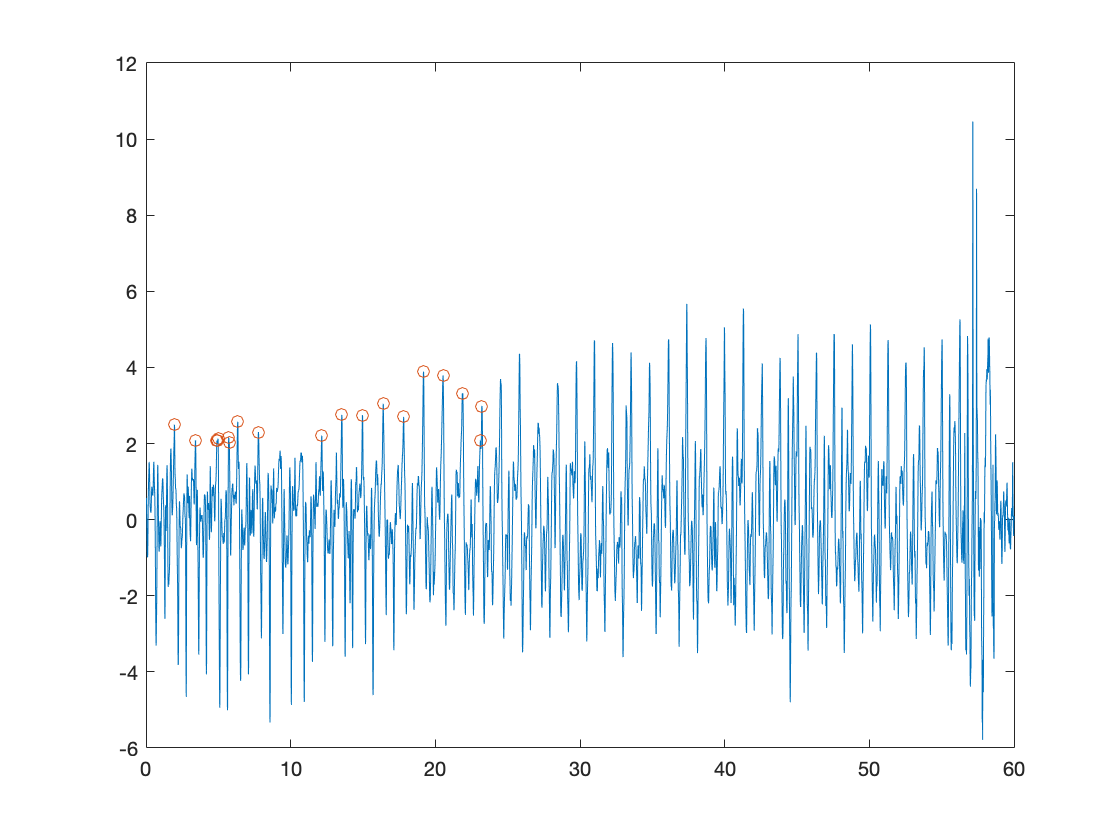

%Walking data
%Create a seperate matrix for motion type
classw = ["walking";"walking"];
i=0;
while i<18
  classw(end+1)= sprintf('walking',1);
  i=i+1;
end
classw;
pw_data=readmatrix('walking-priya.xls');
pwtime = pw_data(:,1);
pwa_x = pw_data(:,2);
%acceleration of x
[pwpktx,pwpkx]=minamp20peaks(1.87,pwtime,pwa_x);
plot(pwtime,pwa_x)
hold on
plot(pwpktx,pwpkx,'o')
hold off

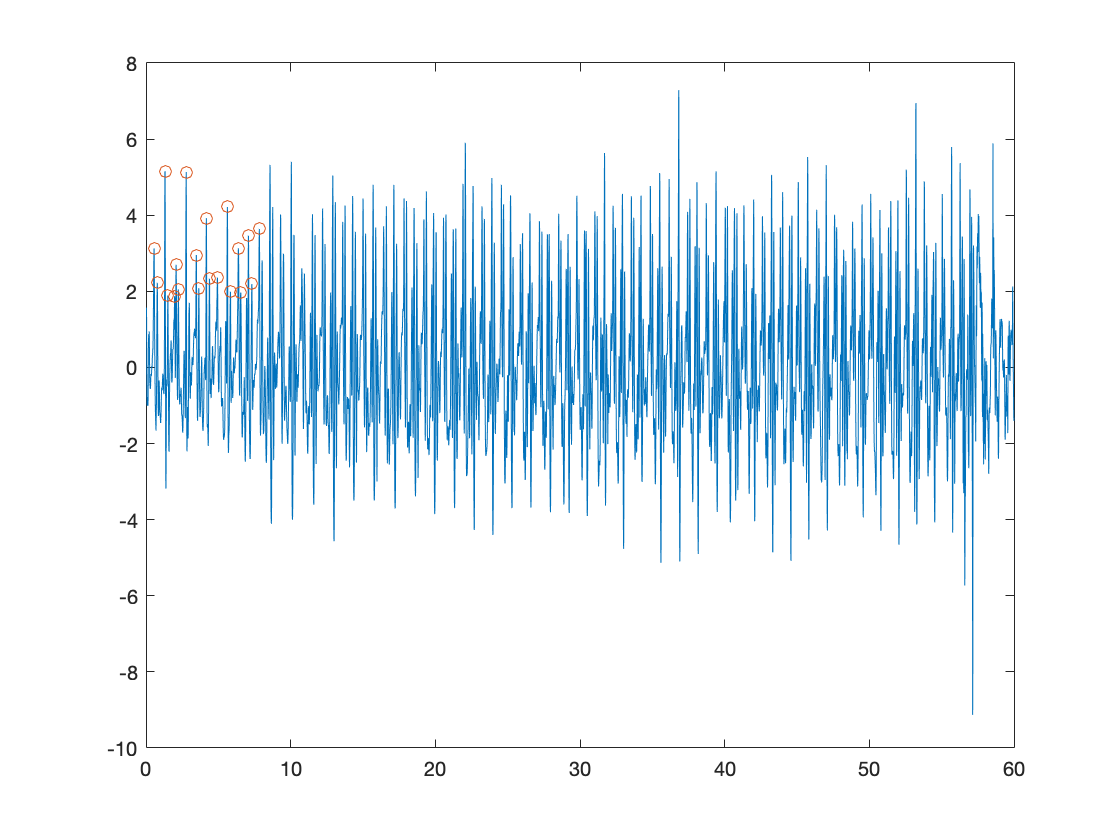

pwpkx1=pwpkx(:);

%acceleration of y
pwa_y = pw_data(:,3);
[pwpkty,pwpky]=minamp20peaks(1.87,pwtime,pwa_y);
plot(pwtime,pwa_y)
hold on
plot(pwpkty,pwpky,'o')
hold off

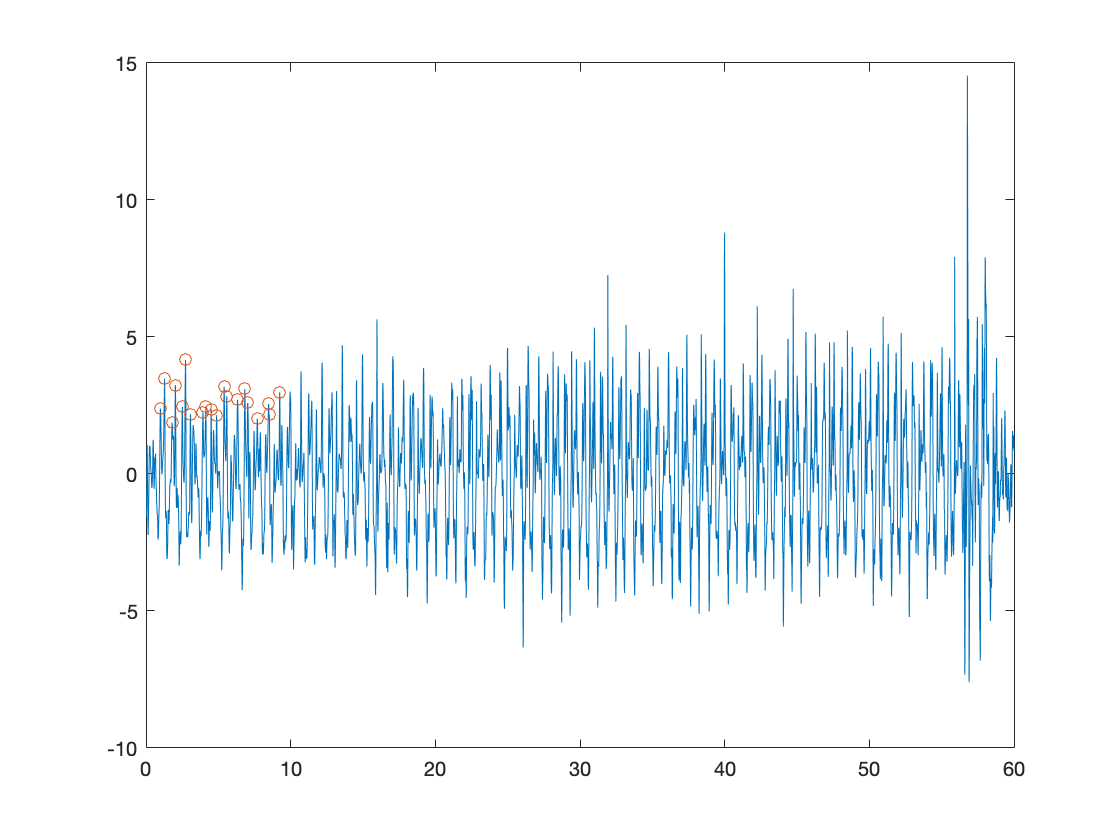

pwpky1=pwpky(:);

%acceleration of z
pwa_z = pw_data(:,4);
[pwpktz,pwpkz]=minamp20peaks(1.87,pwtime,pwa_z);
plot(pwtime,pwa_z)
hold on
plot(pwpktz,pwpkz,'o')
hold off

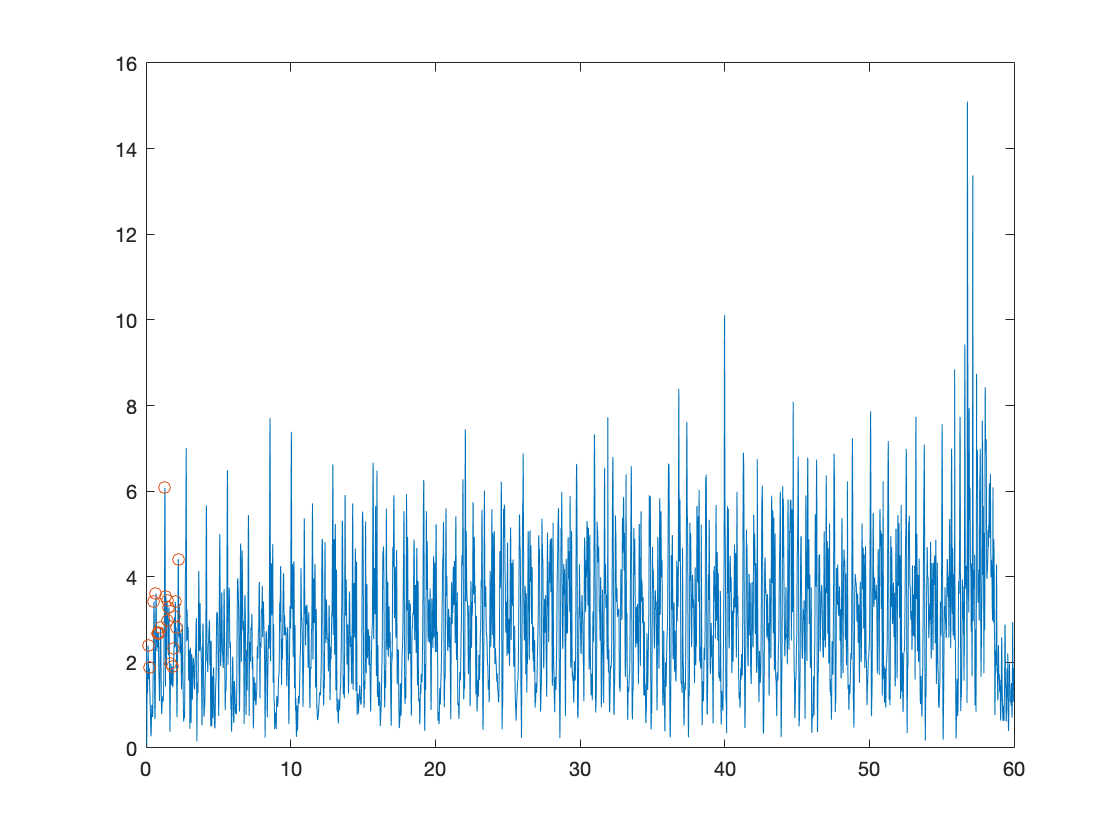

pwpkz1=pwpkz(:);

%absolute acceleration
pwa_abs = pw_data(:,5);
[pwpkta,pwpka]=minamp20peaks(1.87,pwtime,pwa_abs);
plot(pwtime,pwa_abs)
hold on
plot(pwpkta,pwpka,'o')
hold off

pwpka1=pwpka(:);
pwpk=table(pwpkx1,pwpky1,pwpkz1,pwpka1,classw);
pwpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

pwpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    2.4943     3.1287     2.3911      2.3926      "walking"
    2.0844     2.2254     3.4871      1.8728      "walking"
    2.0786     5.1566     1.8741      3.4217      "walking"
    2.0767     1.8884     3.2401      3.6052      "walking"
     2.126     1.8724     2.4553      2.6861      "walking"
    2.1557     2.6988     4.1607      2.6986      "walking"
    2.0218     2.0506     2.1758      2.6641      "walking"
    2.5713     5.1342     2.2472      2.8081      "walking"
    2.3031     2.9543     2.4634      6.0767      "walking"
    2.2074     2.0821     2.3673      3.5403      "walking"
     2.754     3.9251     2.1506      3.4412      "walking"
    2.7467     2.3321     3.182

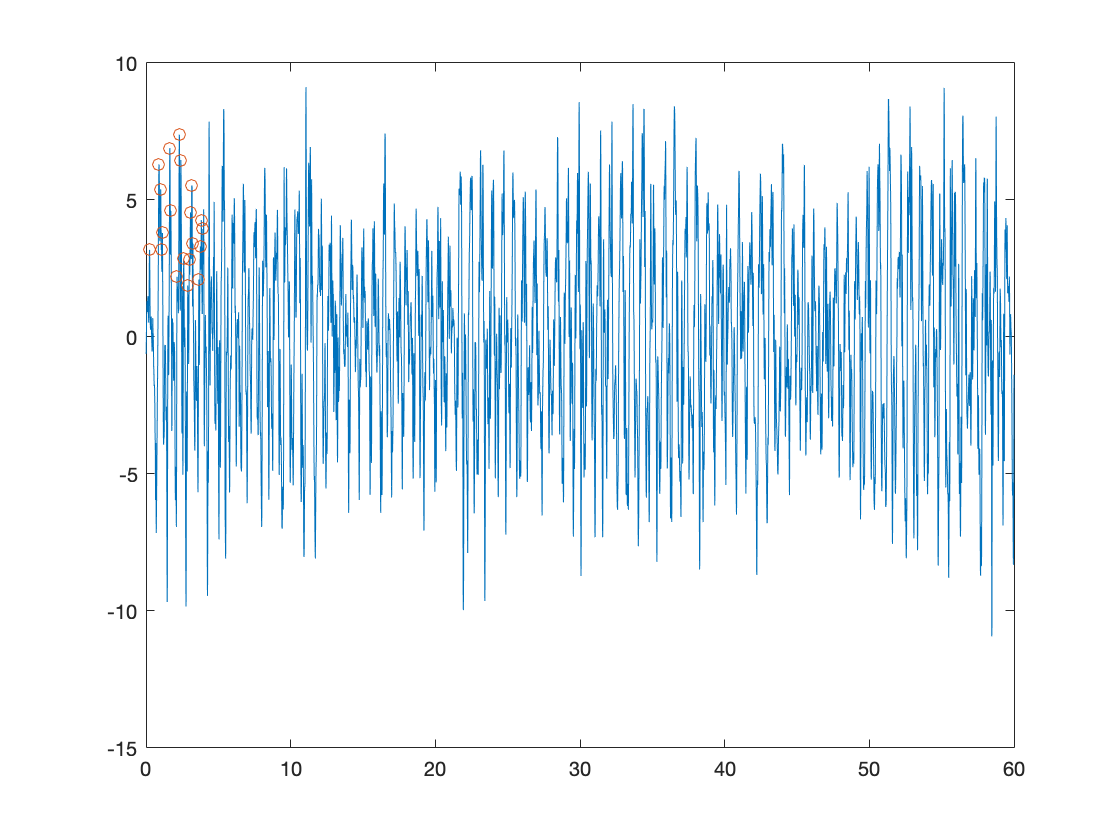


%Running data
classr = ["running";"running"];
i=0;
while i<18
  classr(end+1)= sprintf('running',1);
  i=i+1;
end
classr;
pr_data=readmatrix('running-priya.xls');
prtime = pr_data(:,1);
pra_x = pr_data(:,2);
%acceleration of x
[prpktx,prpkx]=minamp20peaks(1.87,prtime,pra_x);
plot(prtime,pra_x)
hold on
plot(prpktx,prpkx,'o')
hold off

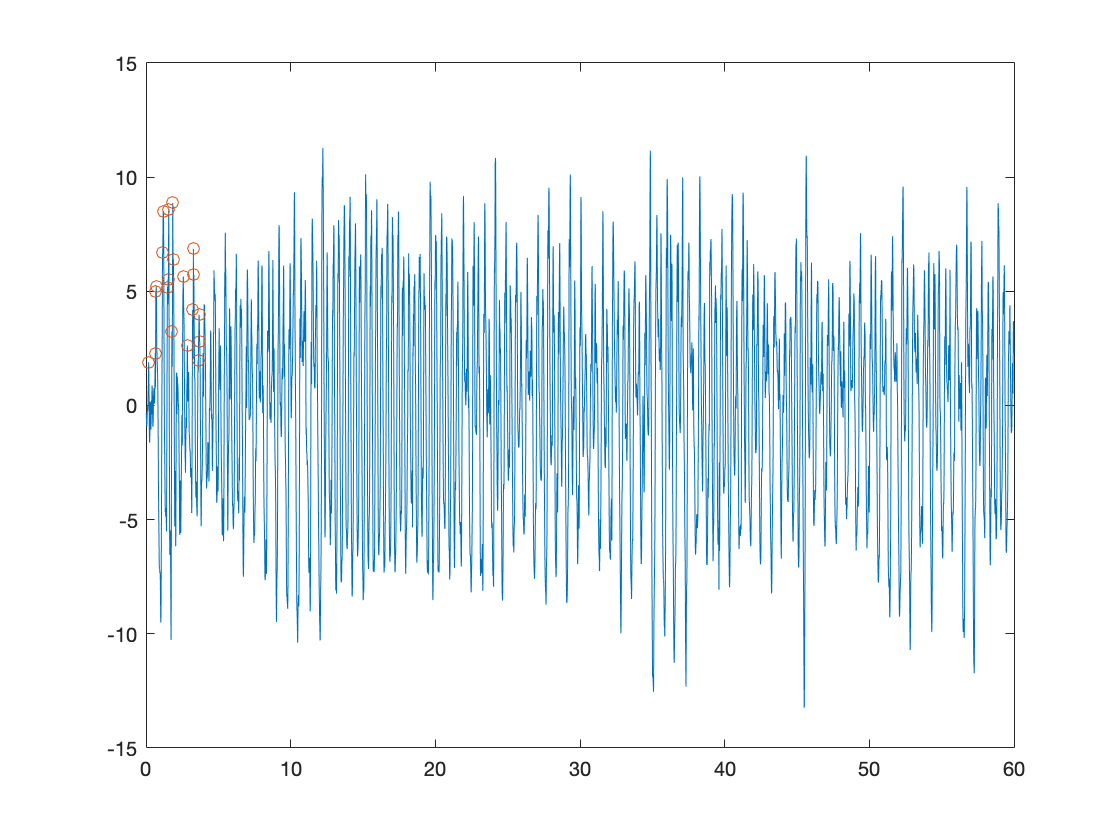

prpkx1=prpkx(:);

%acceleration of y
pra_y = pr_data(:,3);
[prpkty,prpky]=minamp20peaks(1.87,prtime,pra_y);
plot(prtime,pra_y)
hold on
plot(prpkty,prpky,'o')
hold off

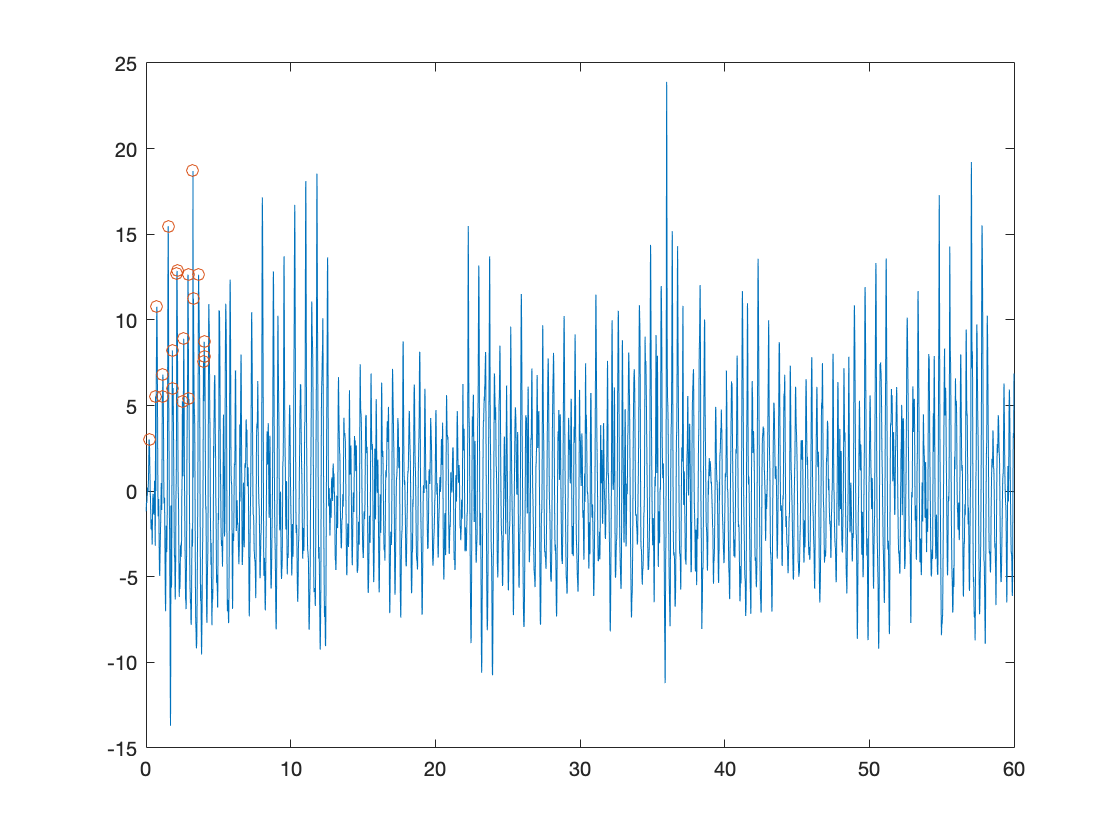

prpky1=prpky(:);

%acceleration of z
pra_z = pr_data(:,4);
[prpktz,prpkz]=minamp20peaks(1.87,prtime,pra_z);
plot(prtime,pra_z)
hold on
plot(prpktz,prpkz,'o')
hold off

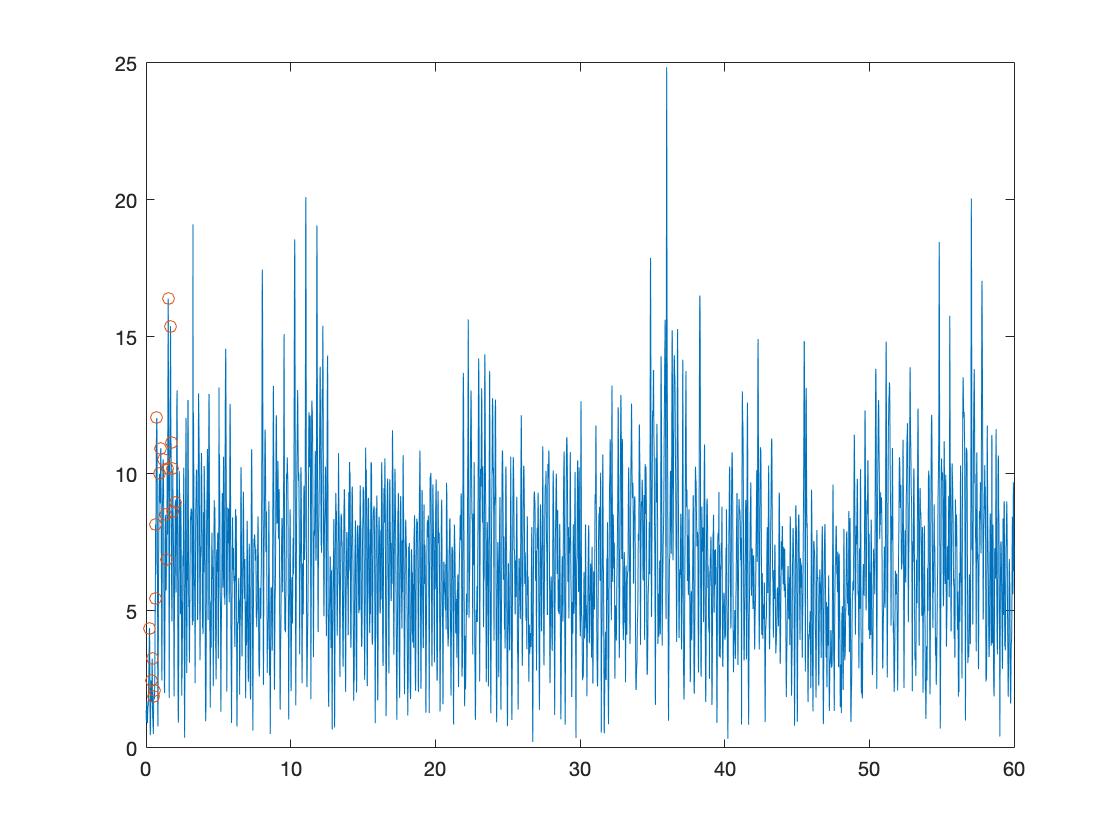

prpkz1=prpkz(:);

%absolute acceleration
pra_abs = pr_data(:,5);
[prpkta,prpka]=minamp20peaks(1.87,prtime,pra_abs);
plot(prtime,pra_abs)
hold on
plot(prpkta,prpka,'o')
hold off

prpka1=prpka(:);
prpk=table(prpkx1,prpky1,prpkz1,prpka1,classr);
prpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

prpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    3.1791     1.8989      3.024      4.3775      "running"
    6.2989     2.2842     5.5321      2.4639      "running"
    5.3931     4.9935     10.766      3.2611      "running"
    3.1959     5.2177     5.5331      1.8856      "running"
    3.7984     6.7076     6.8051      2.0961      "running"
    6.8938     8.4922     15.473      5.4539      "running"
    4.6073     5.1851      8.222      8.1598      "running"
     2.199     5.5232     6.0111      12.045      "running"
    7.3842     8.6017     12.682      10.007      "running"
    6.4578     3.2455     12.862      10.946      "running"
    2.8713     8.8699     5.2446      10.532      "running"
    1.8809     6.4135     8.893

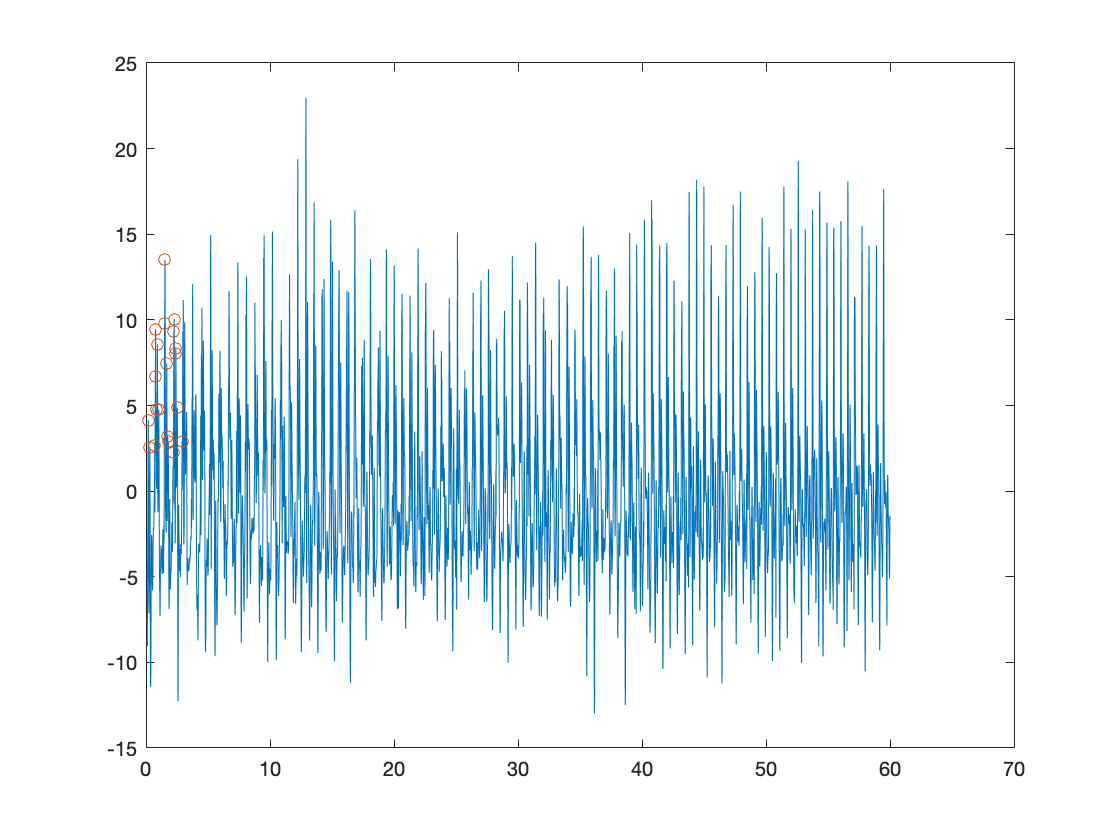



%Jumping data
classj = ["jumping";"jumping"];
i=0;
while i<18
  classj(end+1)= sprintf('jumping',1);
  i=i+1;
end
classj;
pj_data=readmatrix('jumping-priya.xls');
pjtime = pj_data(:,1);
pja_x = pj_data(:,2);
%acceleration of x
[pjpktx,pjpkx]=minamp20peaks(1.87,pjtime,pja_x);
plot(pjtime,pja_x)
hold on
plot(pjpktx,pjpkx,'o')
hold off

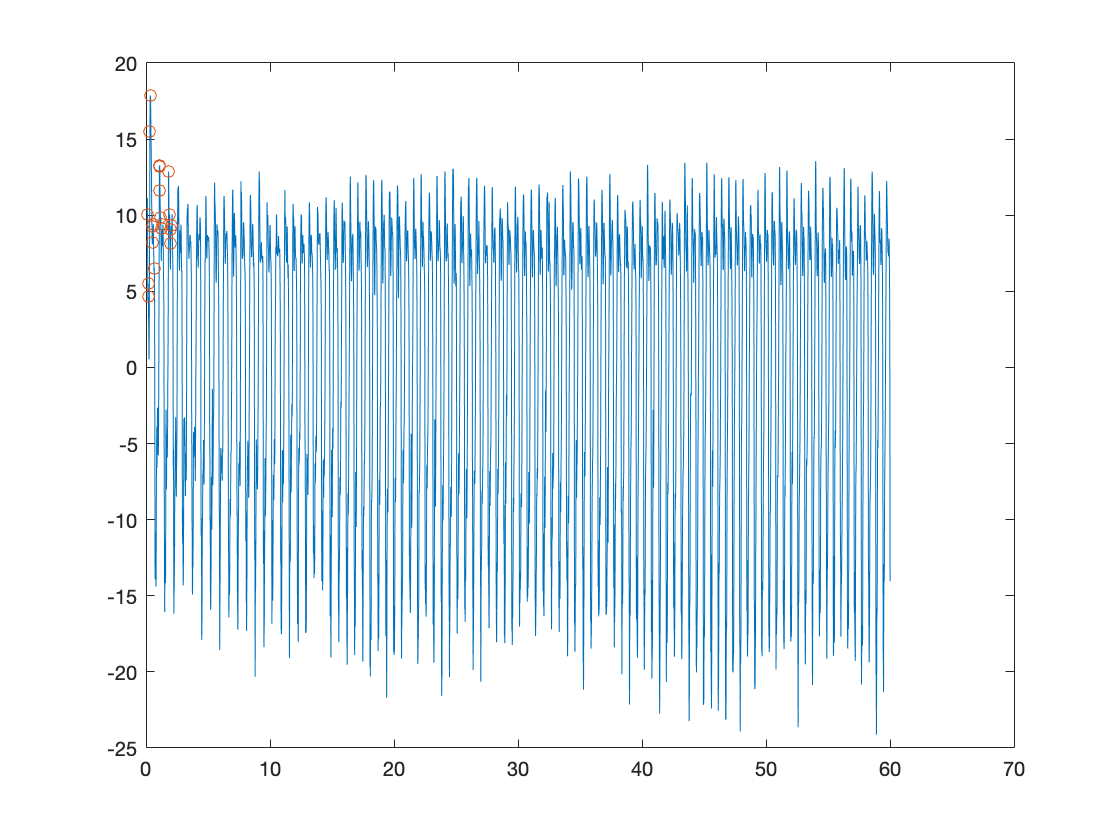

pjpkx1=pjpkx(:);

%acceleration of y
pja_y = pj_data(:,3);
[pjpkty,pjpky]=minamp20peaks(1.87,pjtime,pja_y);
plot(pjtime,pja_y)
hold on
plot(pjpkty,pjpky,'o')
hold off

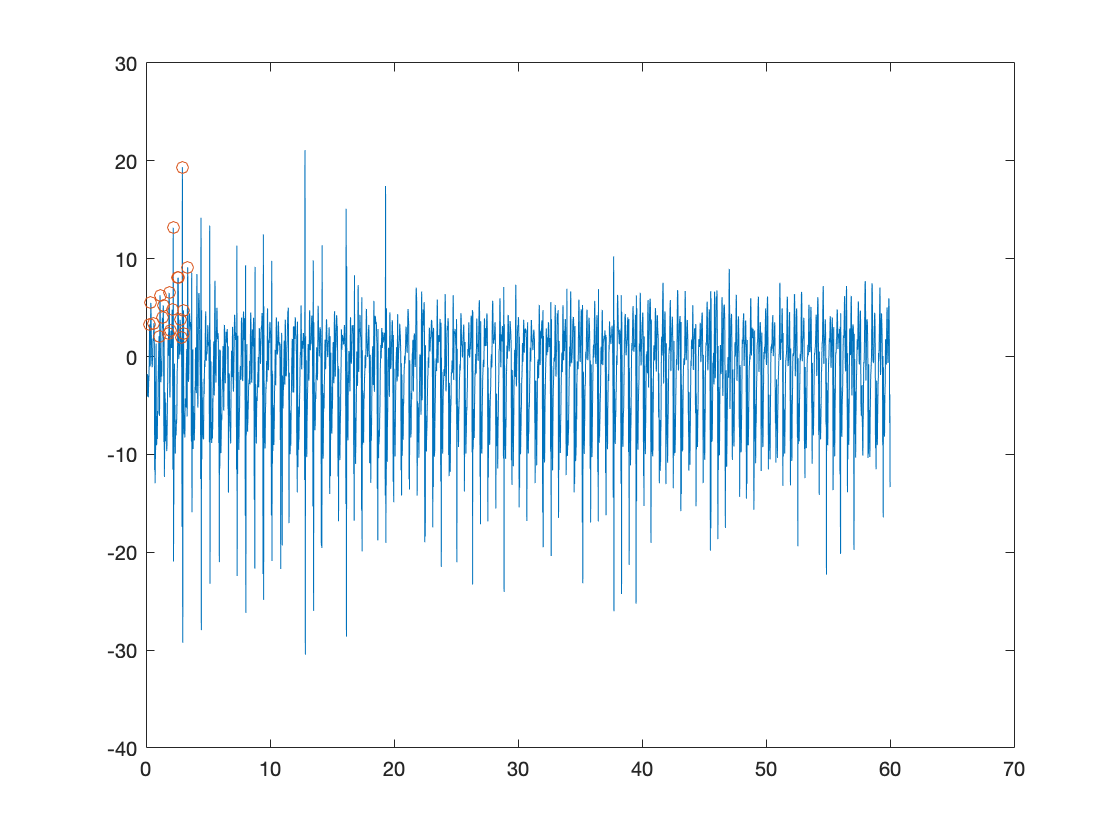

pjpky1=pjpky(:);

%acceleration of z
pja_z = pj_data(:,4);
[pjpktz,pjpkz]=minamp20peaks(1.87,pjtime,pja_z);
plot(pjtime,pja_z)
hold on
plot(pjpktz,pjpkz,'o')
hold off

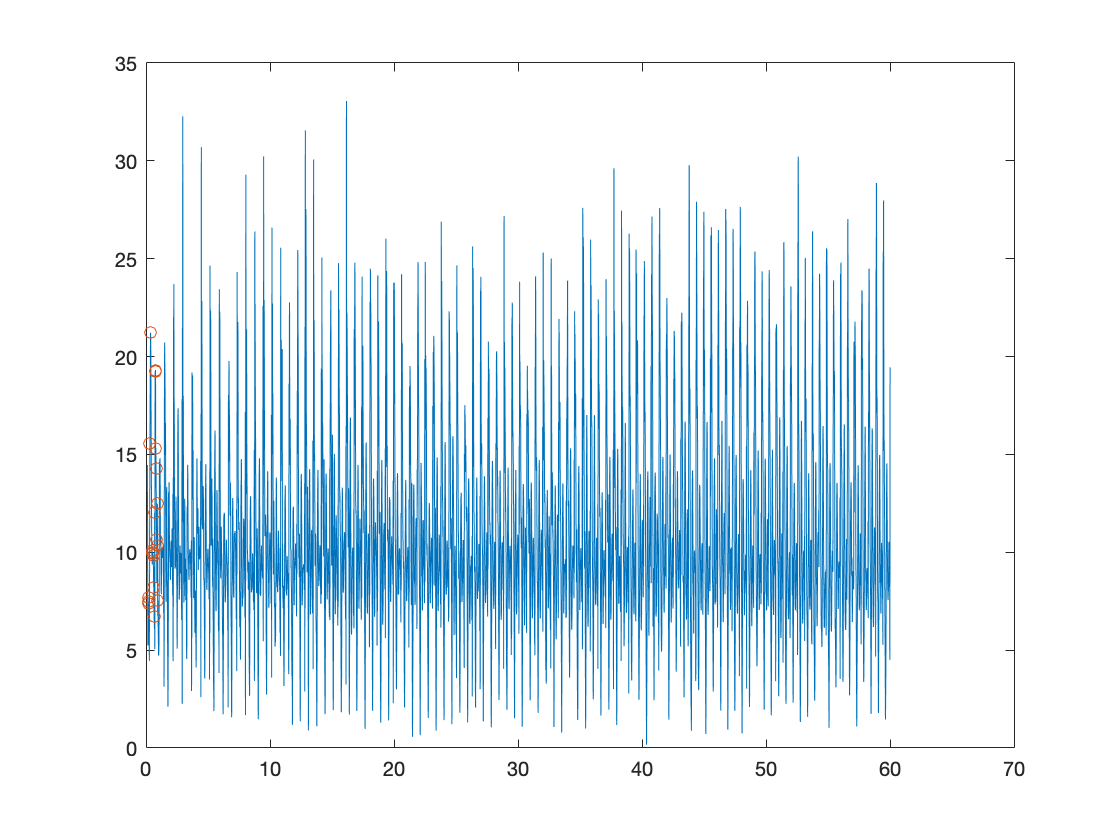

pjpkz1=pjpkz(:);


%absolute acceleration
pja_abs = pj_data(:,5);
[pjpkta,pjpka]=minamp20peaks(1.87,pjtime,pja_abs);
plot(pjtime,pja_abs)
hold on
plot(pjpkta,pjpka,'o')
hold off

pjpka1=pjpka(:);
pjpk=table(pjpkx1,pjpky1,pjpkz1,pjpka1,classj);
pjpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

pjpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    4.1514     10.052      3.285      7.6785      "jumping"
    2.5695     5.5057     5.4854      7.3914      "jumping"
    2.6387      4.635     3.4072      7.4641      "jumping"
    6.7117     15.487     2.0899      15.549      "jumping"
    9.4546     17.857     6.2601      21.215      "jumping"
    4.7638     9.2654     3.9532      10.069      "jumping"
     8.584     8.2077     5.2365      10.002      "jumping"
    4.7536     9.4179     2.3596      9.9619      "jumping"
    9.7814     6.5308     6.5135      9.8314      "jumping"
    13.501     13.175     2.6307      8.2216      "jumping"
    7.4592      11.62     4.7902      6.7089      "jumping"
    3.2039     13.294     13.16

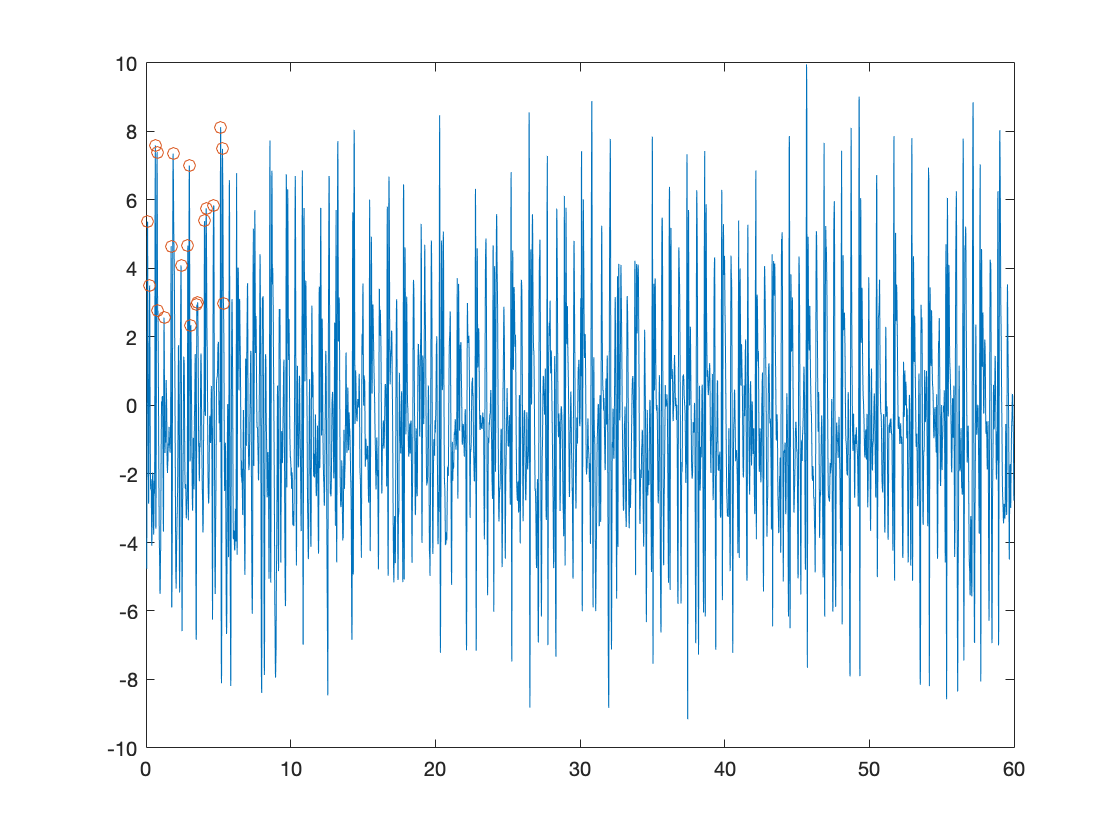

%Walking data
%Create a seperate matrix for motion type

aw_data=readmatrix('walking data (flat) auri.xls');
awtime = aw_data(:,1);
awa_x = aw_data(:,2);
%acceleration of x
[awpktx,awpkx]=minamp20peaks(1.87,awtime,awa_x);
plot(awtime,awa_x)
hold on
plot(awpktx,awpkx,'o')
hold off

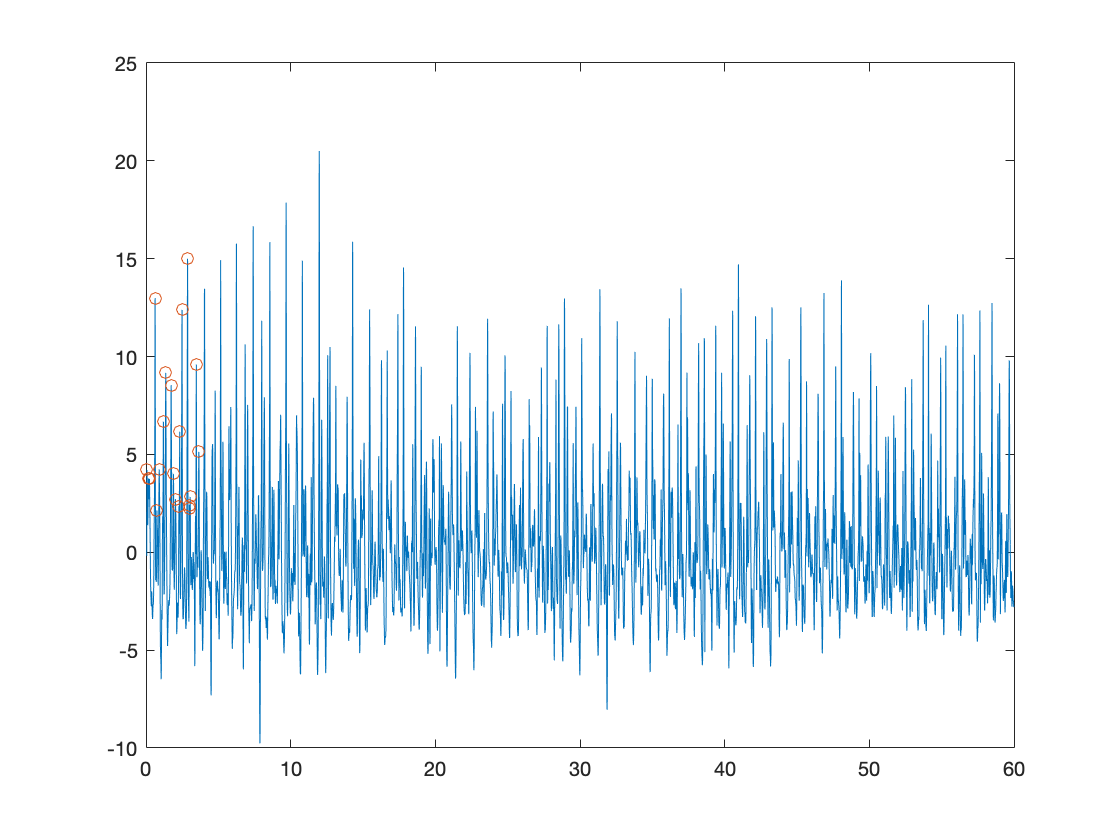

awpkx1=awpkx(:);

%acceleration of y
awa_y = aw_data(:,3);
[awpkty,awpky]=minamp20peaks(1.87,awtime,awa_y);
plot(awtime,awa_y)
hold on
plot(awpkty,awpky,'o')
hold off

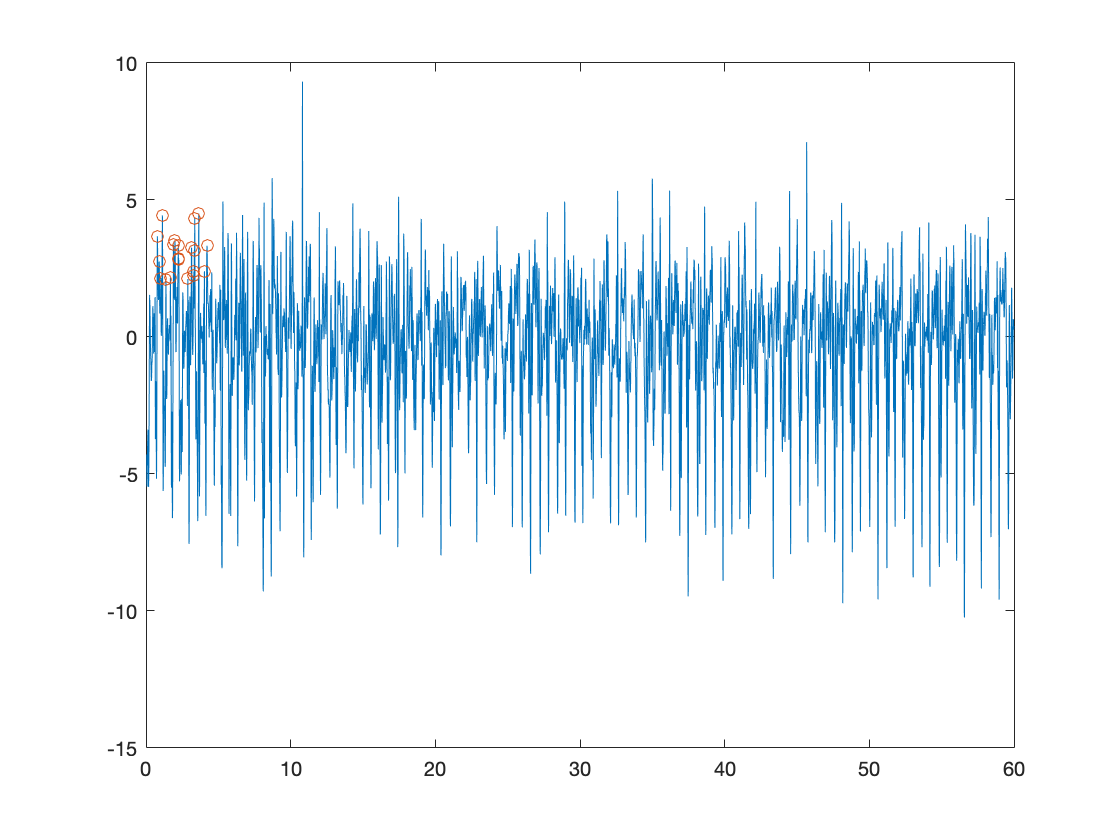

awpky1=awpky(:);

%acceleration of z
awa_z = aw_data(:,4);
[awpktz,awpkz]=minamp20peaks(1.87,awtime,awa_z);
plot(awtime,awa_z)
hold on
plot(awpktz,awpkz,'o')
hold off

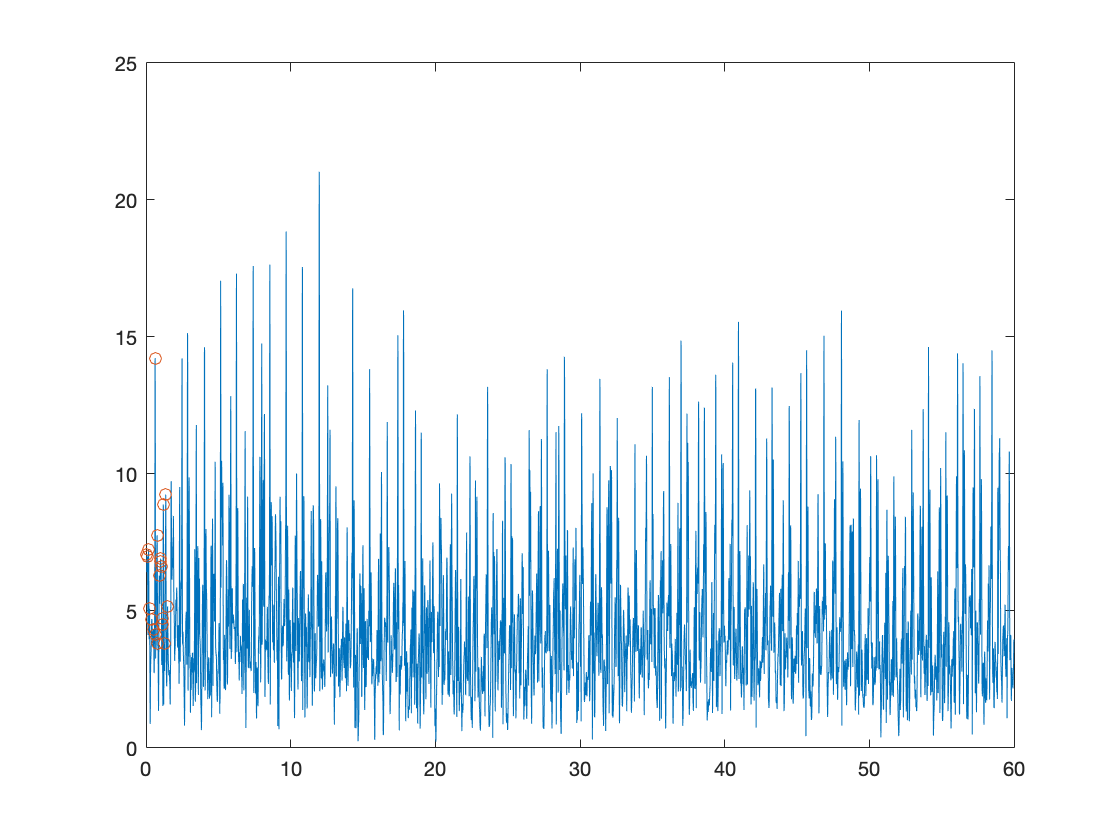

awpkz1=awpkz(:);

%absolute acceleration
awa_abs = aw_data(:,5);
[awpkta,awpka]=minamp20peaks(1.87,awtime,awa_abs);
plot(awtime,awa_abs)
hold on
plot(awpkta,awpka,'o')
hold off

awpka1=awpka(:);
awpk=table(awpkx1,awpky1,awpkz1,awpka1,classw);
awpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

awpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    5.3698     4.2122     3.6781       7.062      "walking"
    3.5045     3.7718     2.7542      6.9787      "walking"
    7.5952     3.7517     2.1517      7.2418      "walking"
    7.3982     12.989     4.4409      5.0794      "walking"
    2.7754     2.1436     2.0942      4.7018      "walking"
    2.5642     4.2369     2.1543      4.3416      "walking"
    4.6537     6.6674     3.3663      14.231      "walking"
    7.3546     9.1647     3.5288      4.1515      "walking"
    4.0893     8.5406     3.3572      7.7661      "walking"
    4.6665     4.0132     2.8768      3.8085      "walking"
     7.007     2.7191     2.8141      6.2916      "walking"
    2.3457     2.3518      2.11

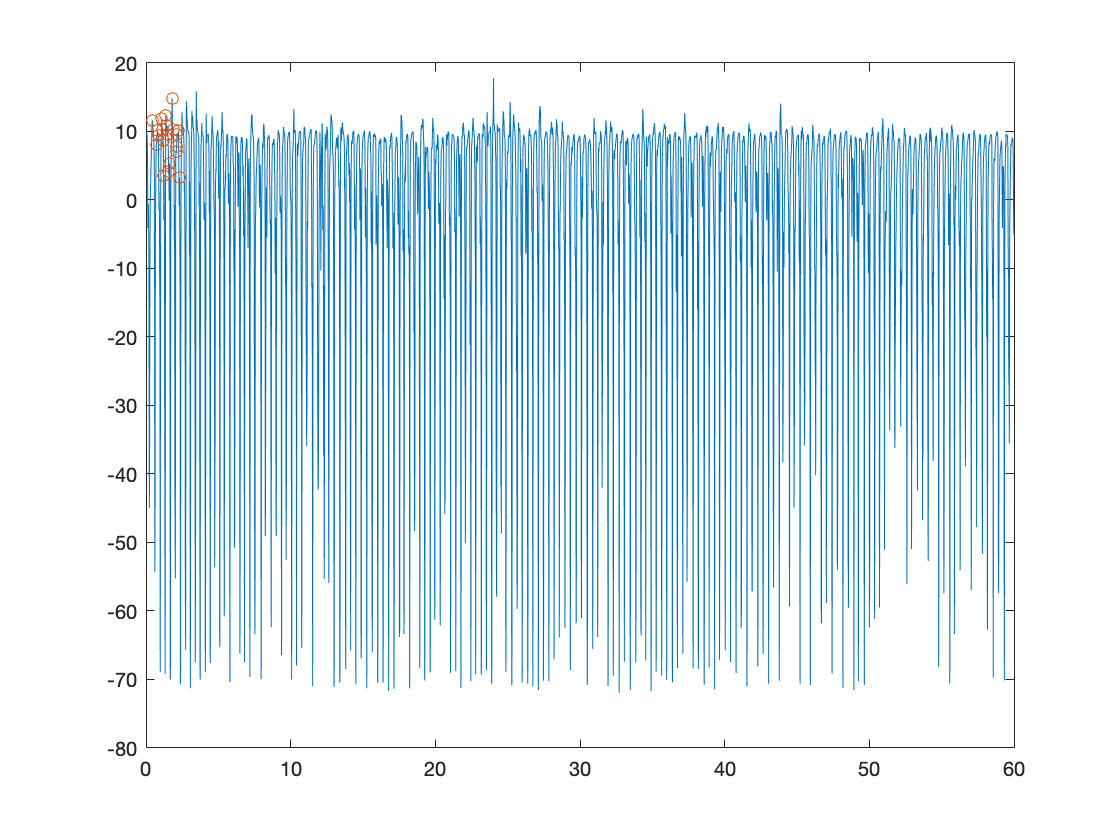


%Running data
ar_data=readmatrix('auri_run.xls');
artime = ar_data(:,1);
ara_x = ar_data(:,2);
%acceleration of x
[arpktx,arpkx]=minamp20peaks(1.87,artime,ara_x);
plot(artime,ara_x)
hold on
plot(arpktx,arpkx,'o')
hold off

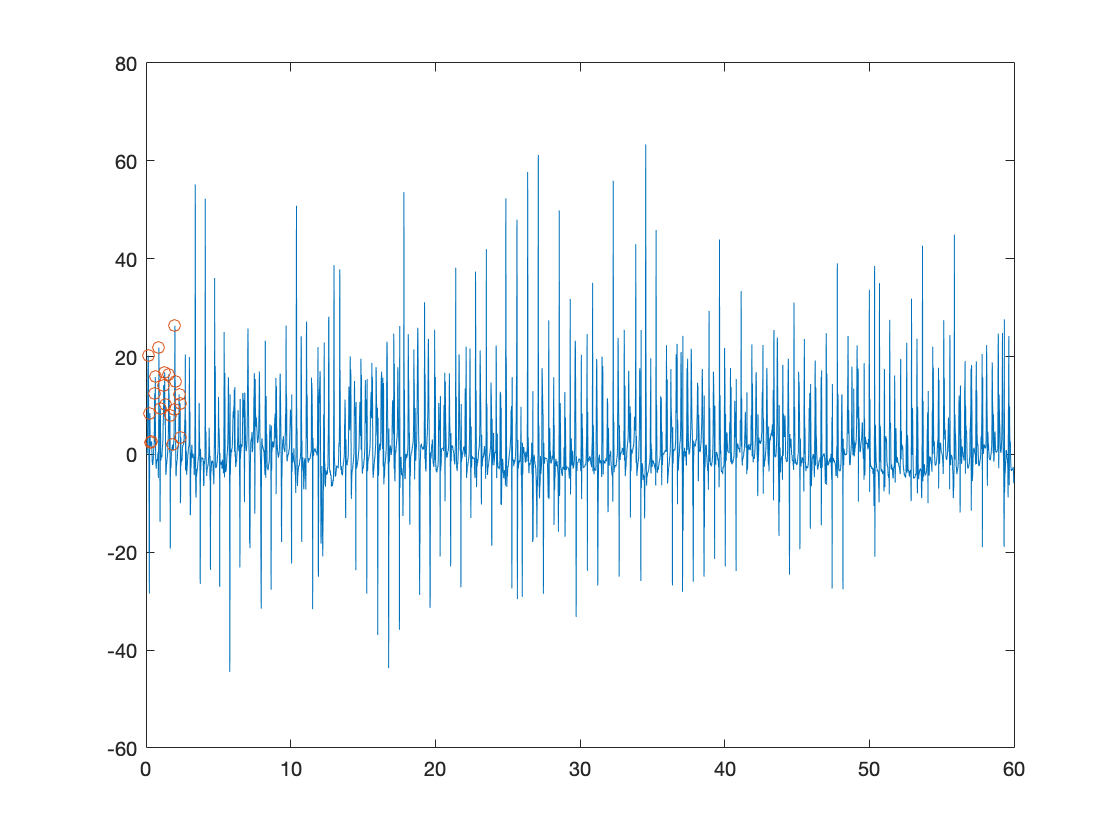

arpkx1=arpkx(:);

%acceleration of y
ara_y = ar_data(:,3);
[arpkty,arpky]=minamp20peaks(1.87,artime,ara_y);
plot(artime,ara_y)
hold on
plot(arpkty,arpky,'o')
hold off

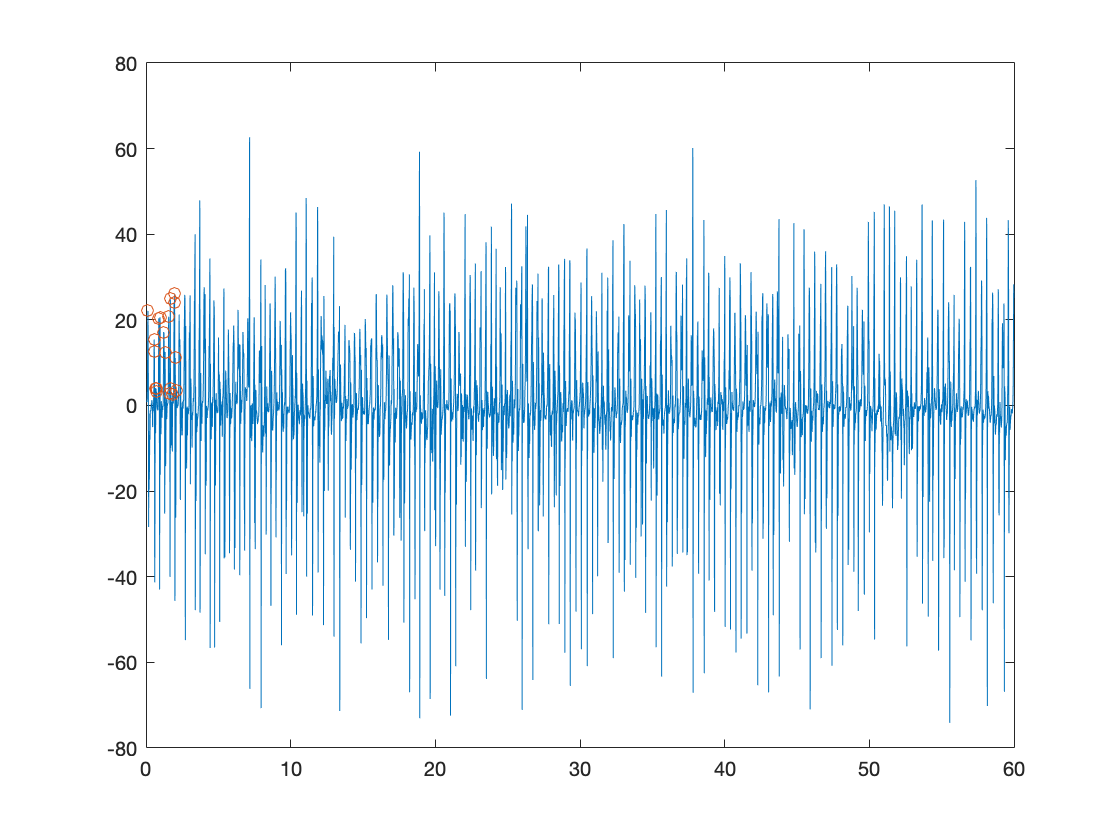

arpky1=arpky(:);

%acceleration of z
ara_z = ar_data(:,4);
[arpktz,arpkz]=minamp20peaks(1.87,artime,ara_z);
plot(artime,ara_z)
hold on
plot(arpktz,arpkz,'o')
hold off

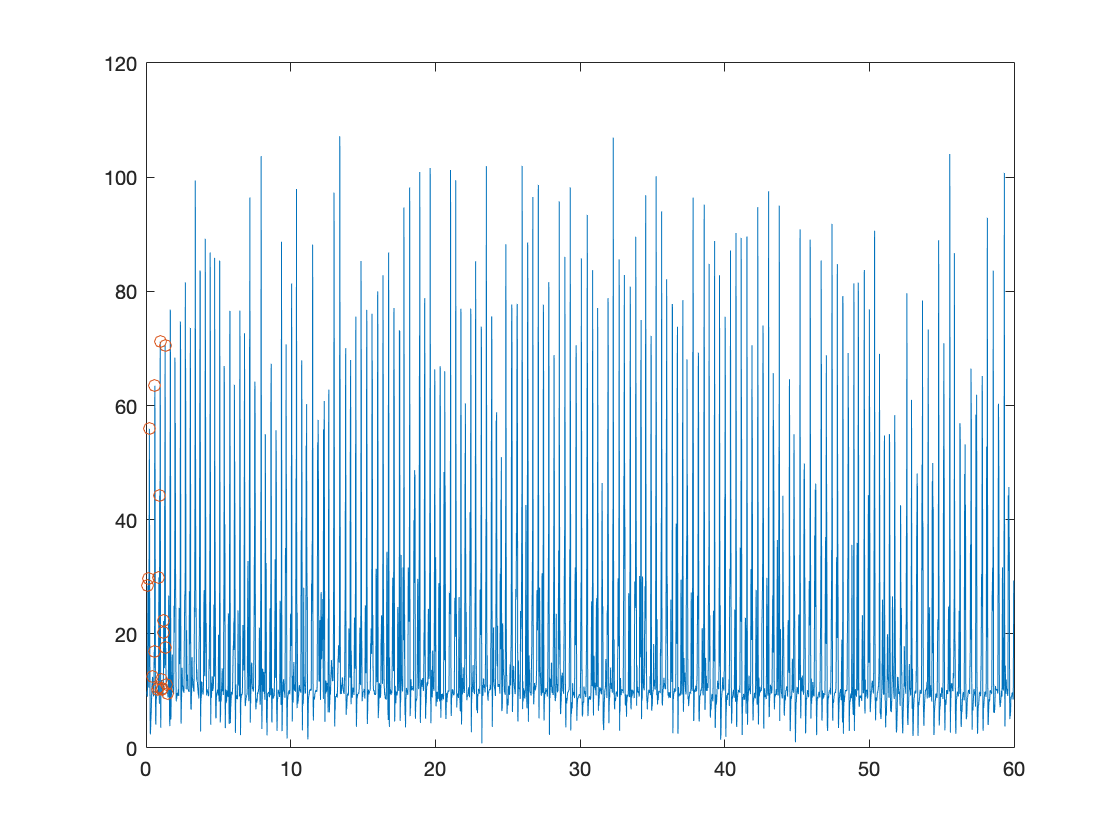

arpkz1=arpkz(:);

%absolute acceleration
ara_abs = ar_data(:,5);
[arpkta,arpka]=minamp20peaks(1.87,artime,ara_abs);
plot(artime,ara_abs)
hold on
plot(arpkta,arpka,'o')
hold off

arpka1=arpka(:);
arpk=table(arpkx1,arpky1,arpkz1,arpka1,classr);
arpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

arpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

     11.62     20.189     22.104      28.459      "running"
    8.0782     8.4488     15.424      29.681      "running"
    10.092     2.5118     12.594      55.916      "running"
    9.3851     2.6647     4.0546       12.45      "running"
    11.903     12.443     3.9919      16.823      "running"
    10.311     15.826      3.202      63.465      "running"
    8.6378     21.822     20.375       10.18      "running"
    3.5287      9.391     20.617      10.659      "running"
    12.404     14.155      17.16      29.887      "running"
    10.835     16.792     17.045      44.255      "running"
    9.5763     10.108     12.454      71.151      "running"
     4.201     16.355     20.73

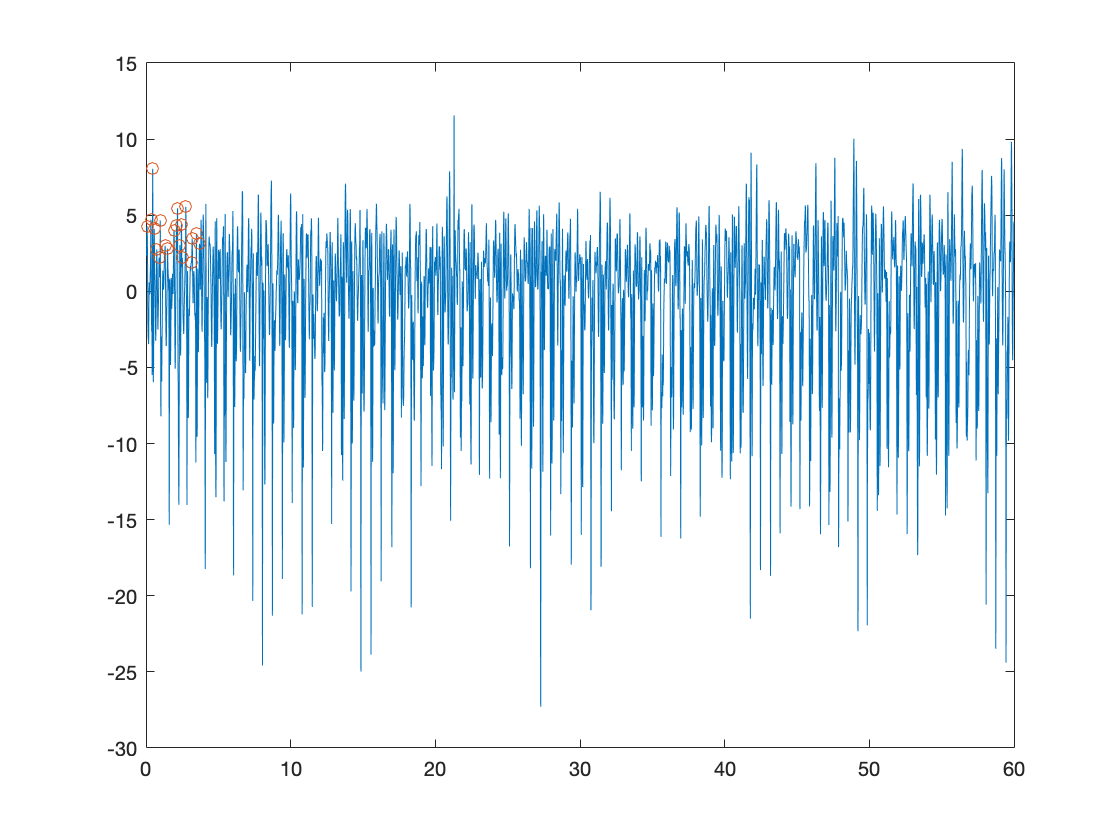


%Jumping data
aj_data=readmatrix('auri_jump.xls');
ajtime = aj_data(:,1);
aja_x = aj_data(:,2);
%acceleration of x
[ajpktx,ajpkx]=minamp20peaks(1.87,ajtime,aja_x);
plot(ajtime,aja_x)
hold on
plot(ajpktx,ajpkx,'o')
hold off

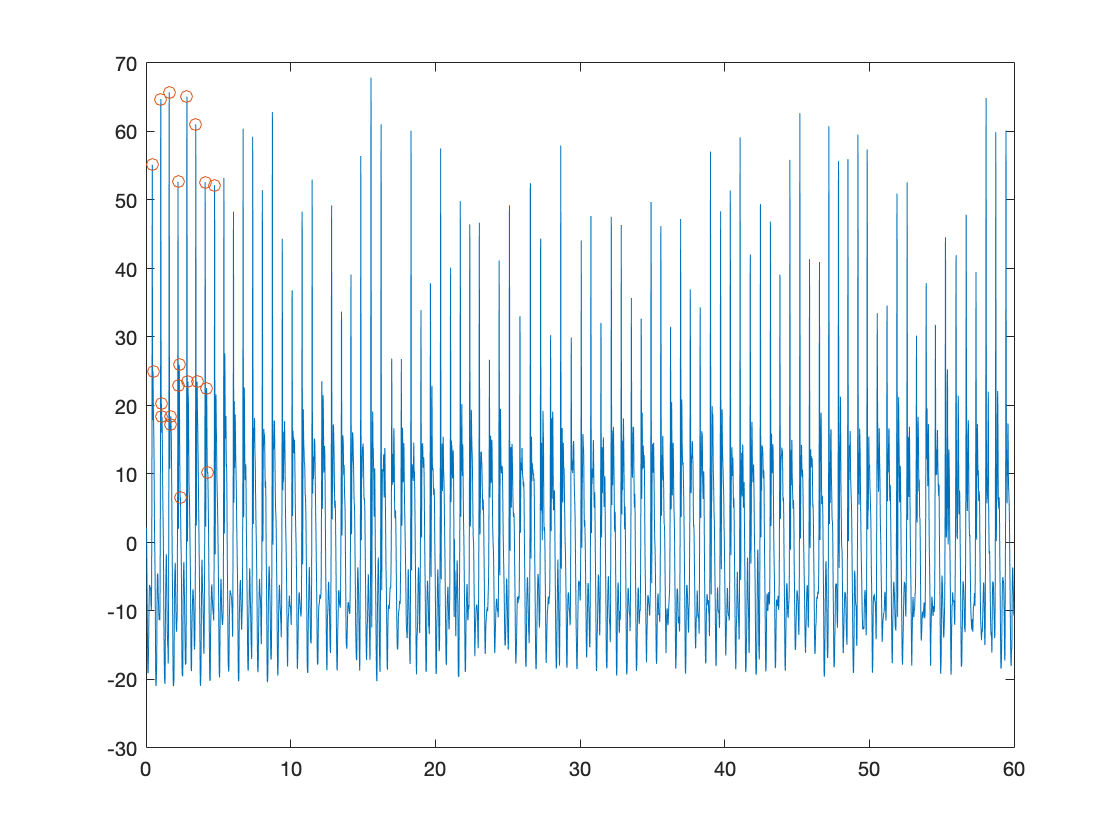

ajpkx1=ajpkx(:);

%acceleration of y
aja_y = aj_data(:,3);
[ajpkty,ajpky]=minamp20peaks(1.87,ajtime,aja_y);
plot(ajtime,aja_y)
hold on
plot(ajpkty,ajpky,'o')
hold off

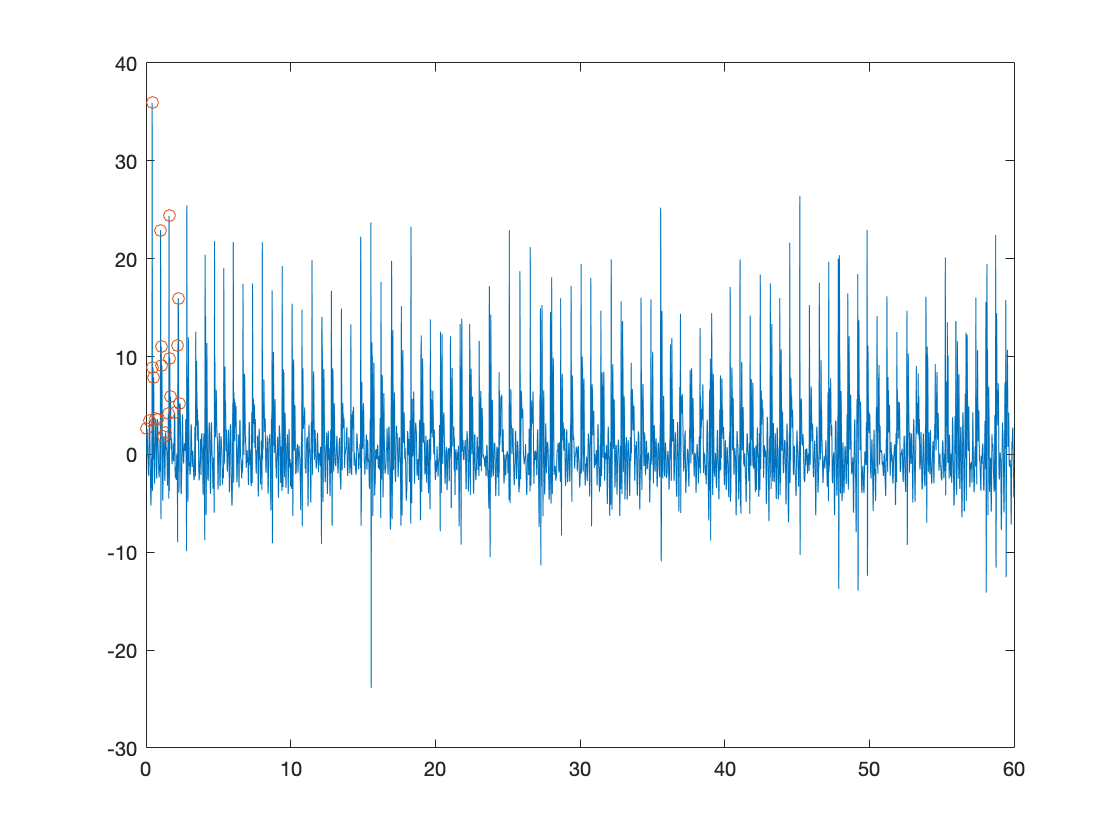

ajpky1=ajpky(:);

%acceleration of z
aja_z = aj_data(:,4);
[ajpktz,ajpkz]=minamp20peaks(1.87,ajtime,aja_z);
plot(ajtime,aja_z)
hold on
plot(ajpktz,ajpkz,'o')
hold off

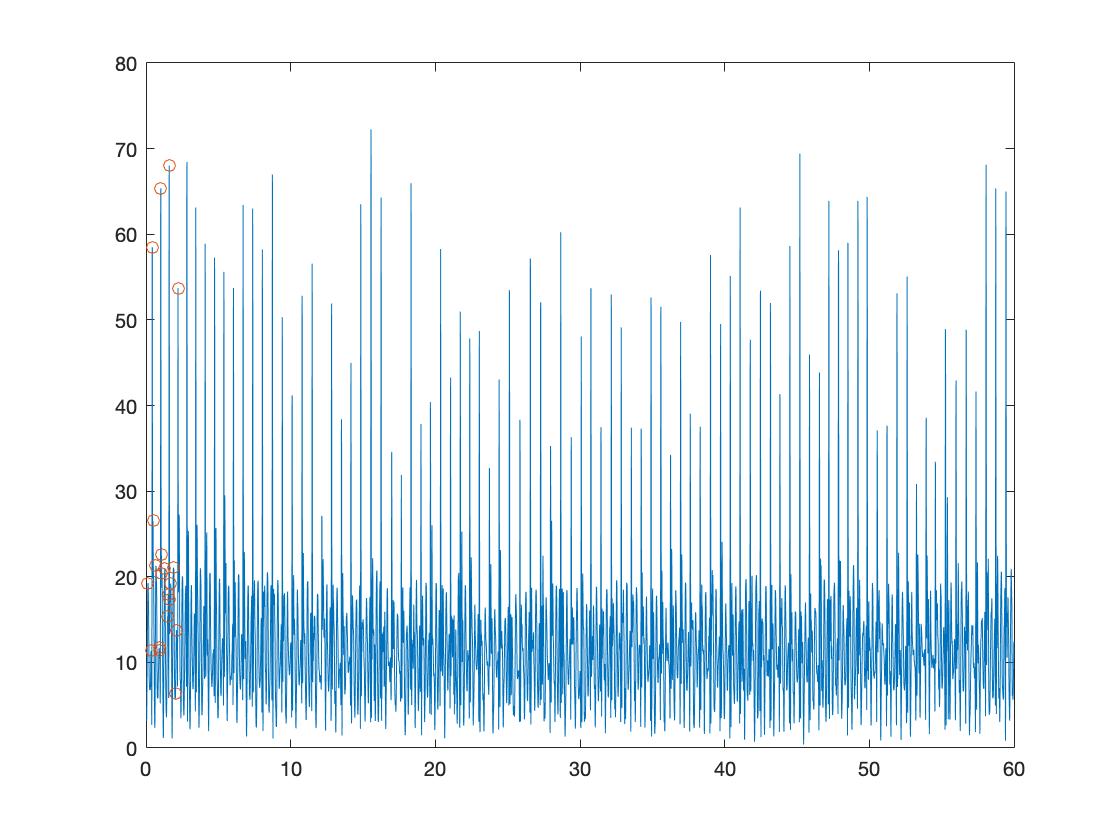

ajpkz1=ajpkz(:);

%absolute acceleration
aja_abs = aj_data(:,5);
[ajpkta,ajpka]=minamp20peaks(1.87,ajtime,aja_abs);
plot(ajtime,aja_abs)
hold on
plot(ajpkta,ajpka,'o')
hold off

ajpka1=ajpka(:);
ajpk=table(ajpkx1,ajpky1,ajpkz1,ajpka1,classj);
ajpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

ajpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    4.2597     55.136     2.6285      19.263      "jumping"
     4.696     25.002     3.4485      11.329      "jumping"
    8.0463     64.743     35.923      58.481      "jumping"
    4.1087     20.274     8.8997       26.53      "jumping"
    2.7589     18.322     7.8837      21.274      "jumping"
    2.2131     65.733     3.6532      11.697      "jumping"
    4.6584     17.167     3.6104      11.386      "jumping"
     2.997     18.414     22.923      65.388      "jumping"
    2.8074     52.665     11.027      22.543      "jumping"
    4.0205     22.894     9.0955      20.377      "jumping"
    4.3369     25.948     1.8764       20.96      "jumping"
    5.4571     6.5841     2.255

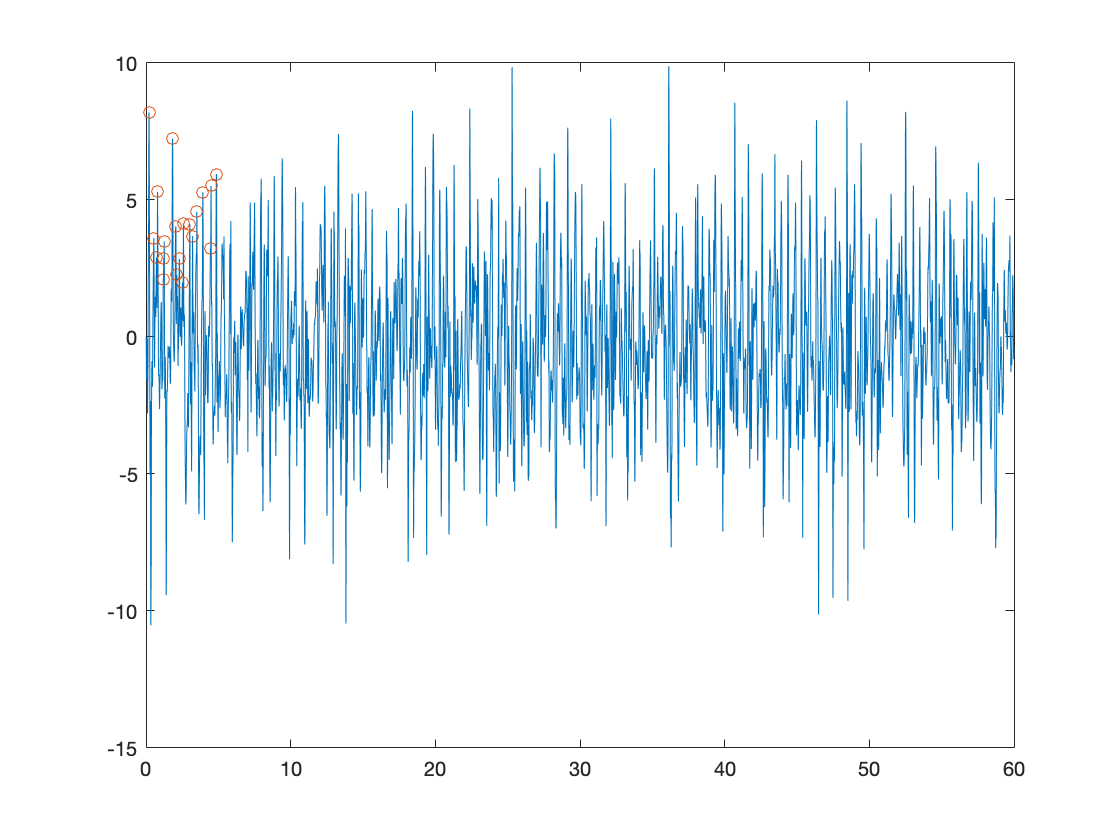

%Walking data
%Create a seperate matrix for motion type

sw_data=readmatrix('walking(flat)_sharon.xls');
swtime = sw_data(:,1);
swa_x = sw_data(:,2);
%acceleration of x
[swpktx,swpkx]=minamp20peaks(1.87,swtime,swa_x);
plot(swtime,swa_x)
hold on
plot(swpktx,swpkx,'o')
hold off

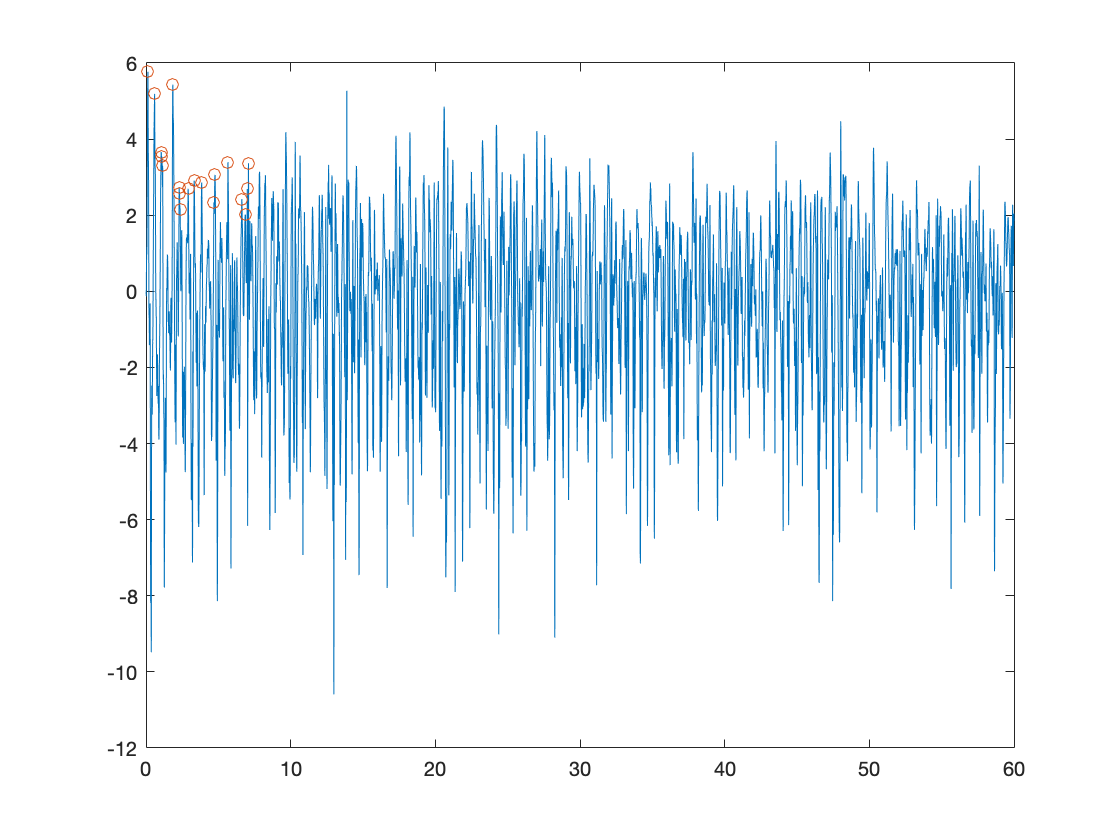

swpkx1=swpkx(:);

%acceleration of y
swa_y = sw_data(:,3);
[swpkty,swpky]=minamp20peaks(1.87,swtime,swa_y);
plot(swtime,swa_y)
hold on
plot(swpkty,swpky,'o')
hold off

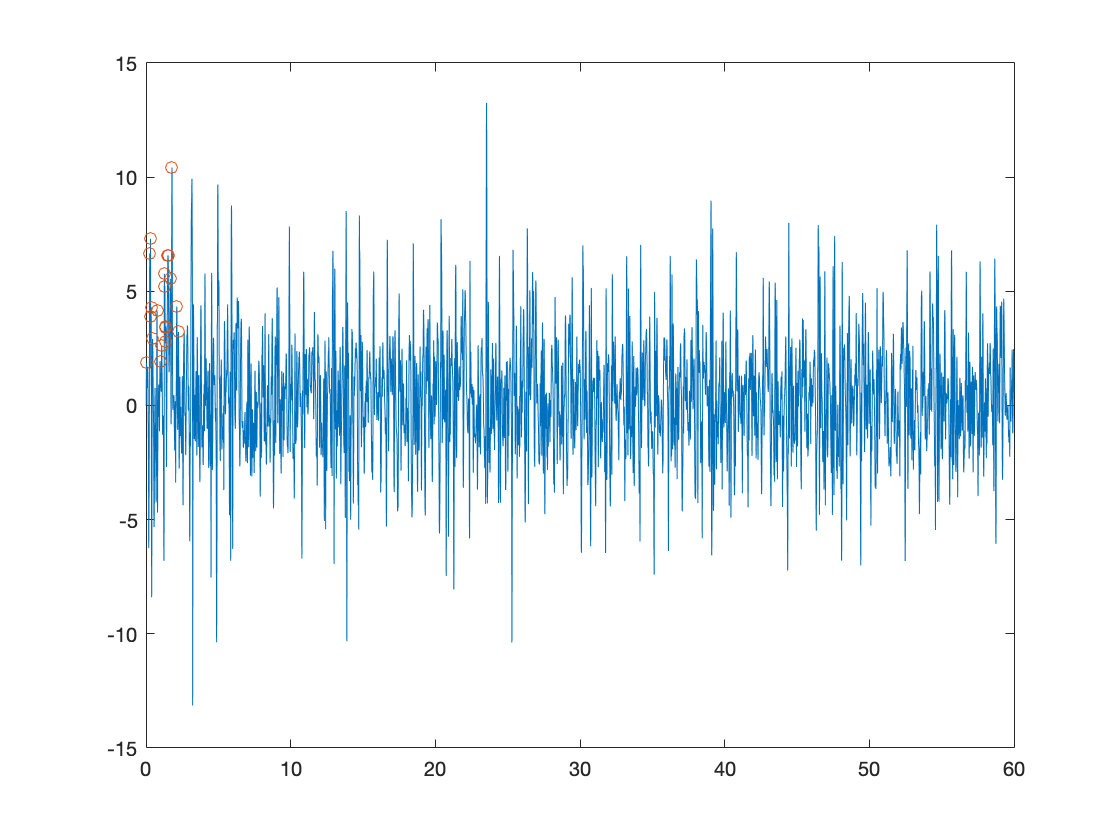

swpky1=swpky(:);

%acceleration of z
swa_z = sw_data(:,4);
[swpktz,swpkz]=minamp20peaks(1.87,swtime,swa_z);
plot(swtime,swa_z)
hold on
plot(swpktz,swpkz,'o')
hold off

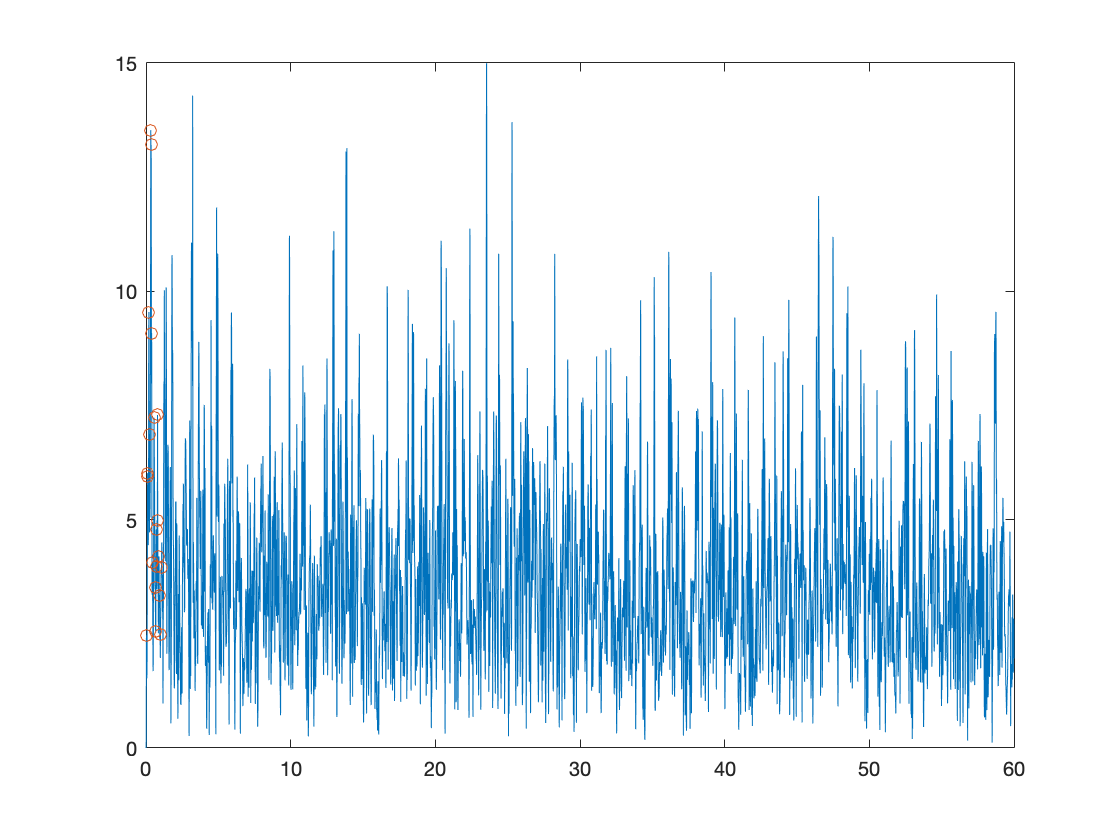

swpkz1=swpkz(:);


%absolute acceleration
swa_abs = sw_data(:,5);
[swpkta,swpka]=minamp20peaks(1.87,swtime,swa_abs);
plot(swtime,swa_abs)
hold on
plot(swpkta,swpka,'o')
hold off

swpka1=swpka(:);
swpk=table(swpkx1,swpky1,swpkz1,swpka1,classw);
swpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

swpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    8.1969     5.7687     1.8732      2.4686      "walking"
     3.609     5.1893     6.6498      6.0219      "walking"
    2.9019     3.6601     7.3014      5.9441      "walking"
    5.3003     3.5353     3.8925      9.5468      "walking"
    2.1158      3.298     4.3118      6.8686      "walking"
    2.8764       5.43     2.9178       13.53      "walking"
    3.4888     2.7212     4.1722      13.205      "walking"
     7.241     2.5834     1.9437      9.0866      "walking"
    4.0377     2.1535     2.6296       4.066      "walking"
    2.2778     2.6958     5.7726      7.2345      "walking"
    2.8505     2.9094     5.2266      3.5139      "walking"
     1.989     2.8606     3.432

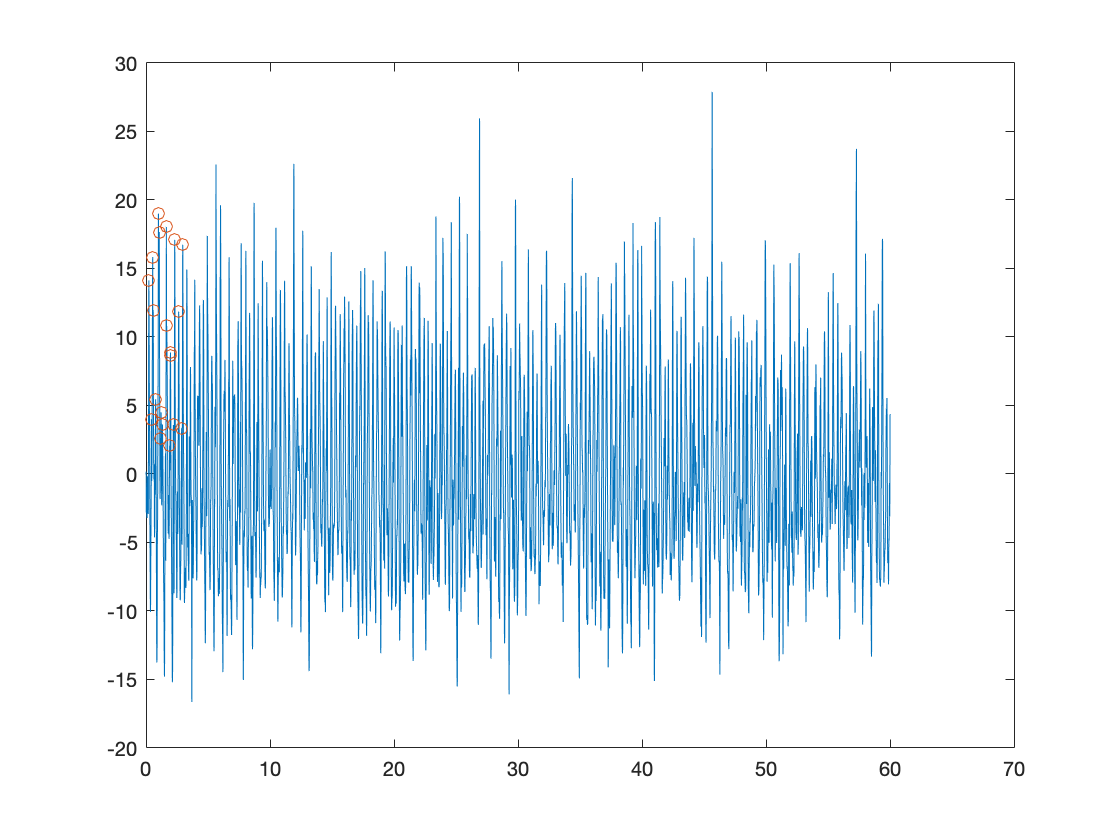


%Running data
sr_data=readmatrix('running(flat)_sharon.xls');
srtime = sr_data(:,1);
sra_x = sr_data(:,2);
%acceleration of x
[srpktx,srpkx]=minamp20peaks(1.87,srtime,sra_x);
plot(srtime,sra_x)
hold on
plot(srpktx,srpkx,'o')
hold off

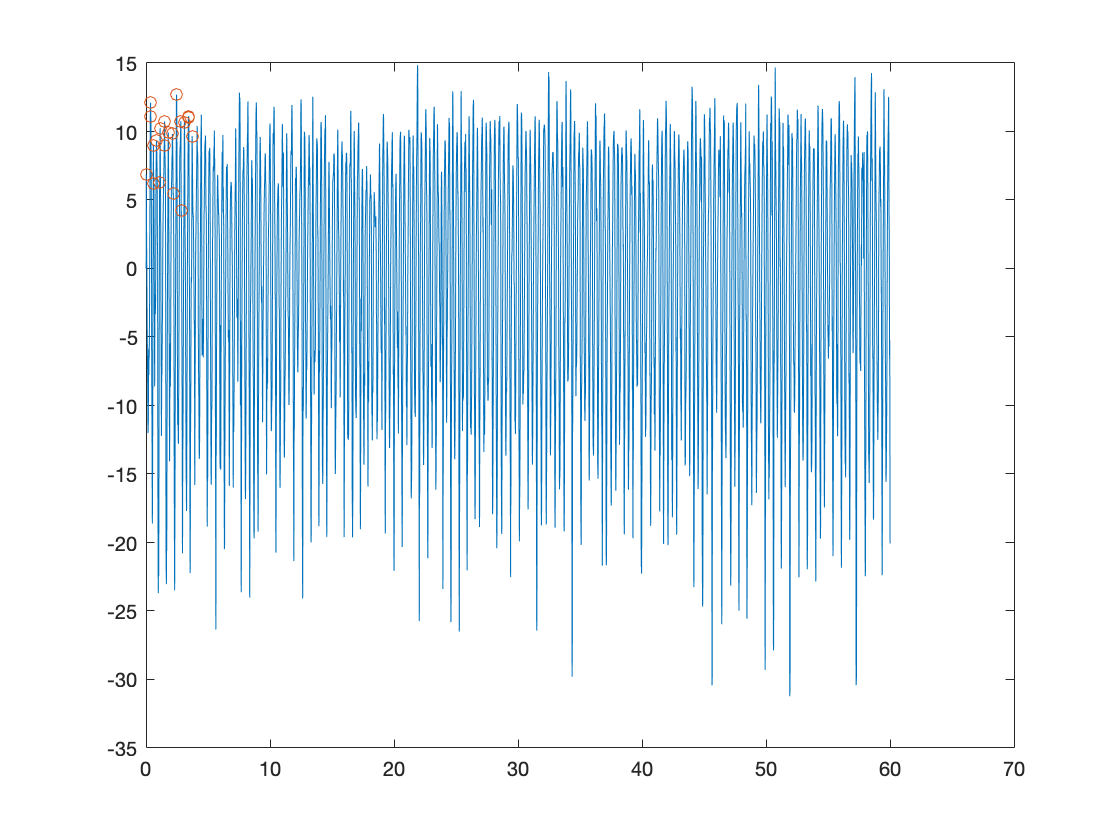

srpkx1=srpkx(:);

%acceleration of y
sra_y = sr_data(:,3);
[srpkty,srpky]=minamp20peaks(1.87,srtime,sra_y);
plot(srtime,sra_y)
hold on
plot(srpkty,srpky,'o')
hold off

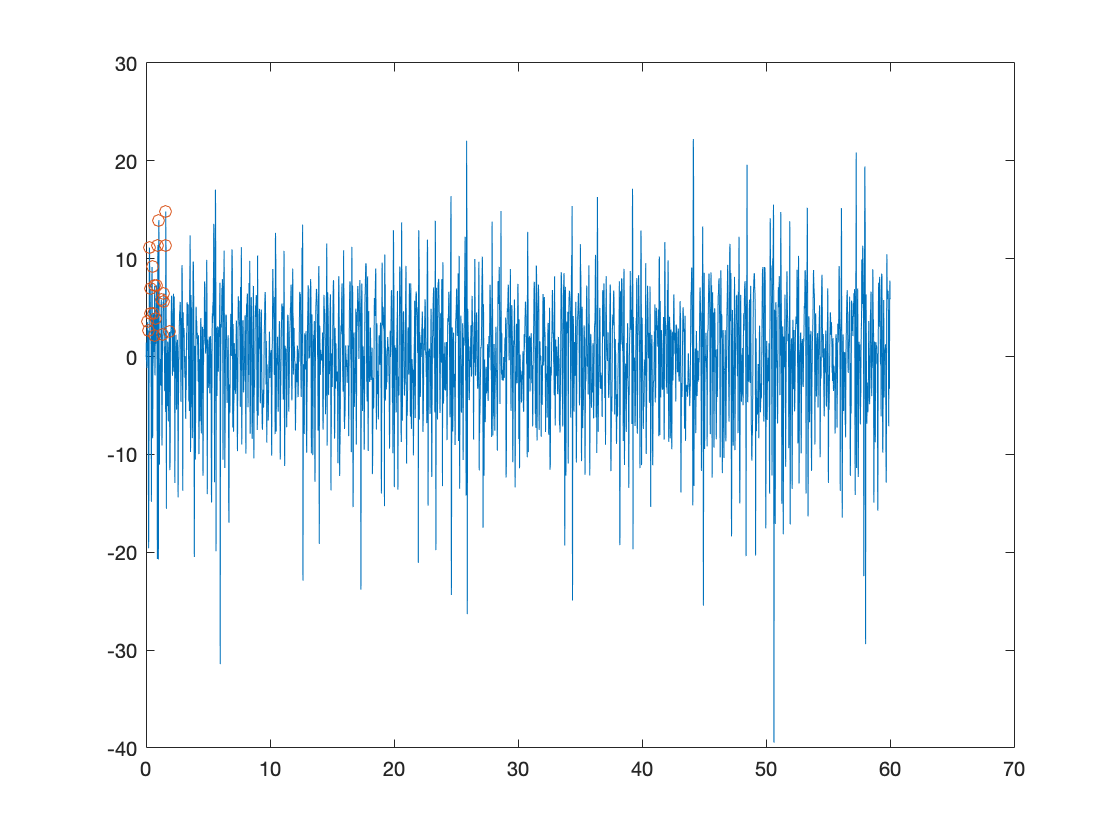

srpky1=srpky(:);

%acceleration of z
sra_z = sr_data(:,4);
[srpktz,srpkz]=minamp20peaks(1.87,srtime,sra_z);
plot(srtime,sra_z)
hold on
plot(srpktz,srpkz,'o')
hold off

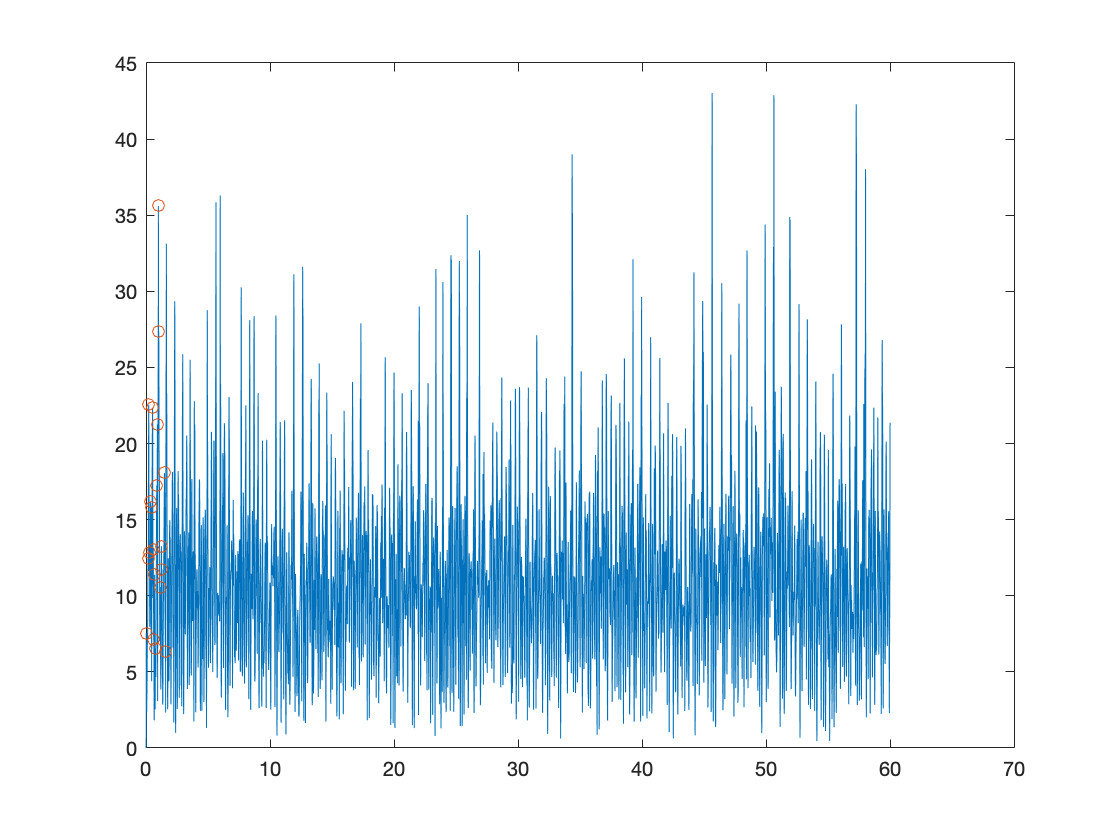

srpkz1=srpkz(:);

%absolute acceleration
sra_abs = sr_data(:,5);
[srpkta,srpka]=minamp20peaks(1.87,srtime,sra_abs);
plot(srtime,sra_abs)
hold on
plot(srpkta,srpka,'o')
hold off

srpka1=srpka(:);
srpk=table(srpkx1,srpky1,srpkz1,srpka1,classr);
srpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

srpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    14.133     6.8496      3.551      7.5472      "running"
    3.9962     12.103     2.6801      12.429      "running"
    15.826     11.068     11.127       22.55      "running"
    11.959     8.9889     6.9234      12.813      "running"
    5.4536     6.1982     4.3607      16.192      "running"
    19.008     9.3261     9.1557      15.823      "running"
     17.66     6.3101     4.4062      22.353      "running"
    2.5799     10.248     2.1546      13.054      "running"
    4.5019     8.9983     7.2127      7.1424      "running"
    3.6066     10.743     3.8662      11.384      "running"
    18.037     9.9286     7.2737      6.5187      "running"
    10.826     9.8201     11.39

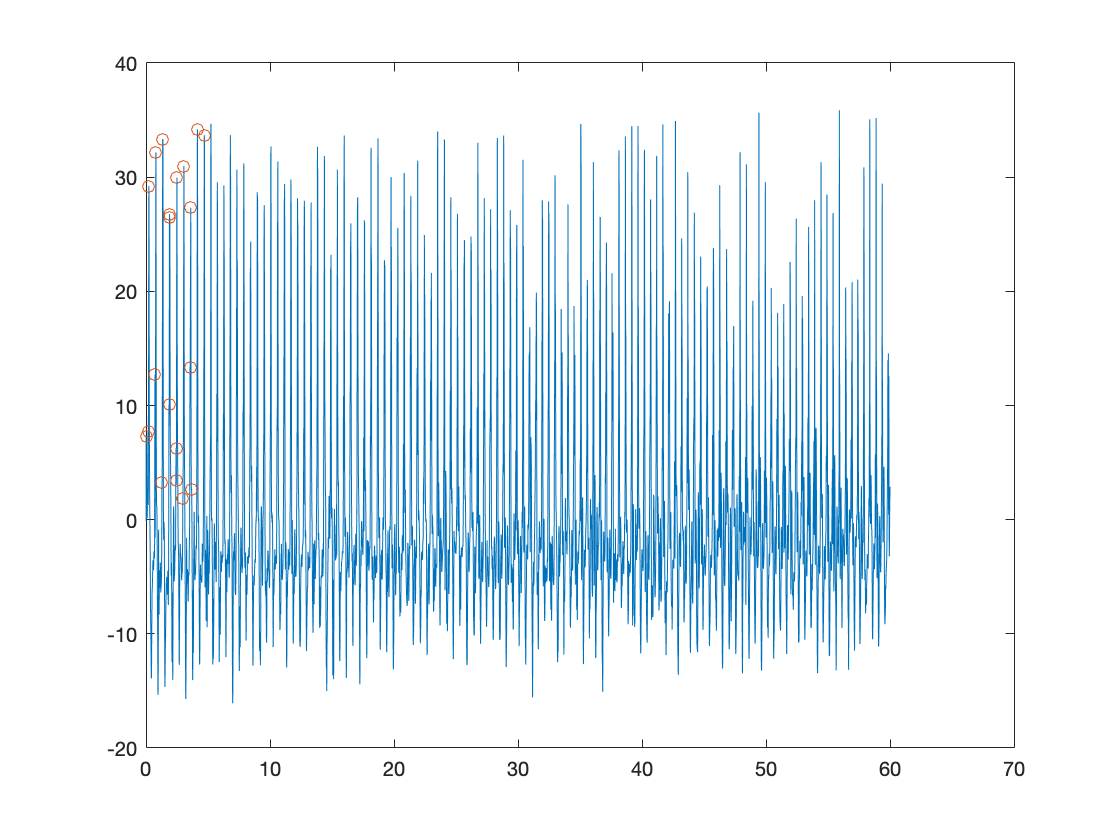


%Jumping data
sj_data=readmatrix('jumping(flat)_sharon.xls');
sjtime = sj_data(:,1);
sja_x = sj_data(:,2);
%acceleration of x
[sjpktx,sjpkx]=minamp20peaks(1.87,sjtime,sja_x);
plot(sjtime,sja_x)
hold on
plot(sjpktx,sjpkx,'o')
hold off

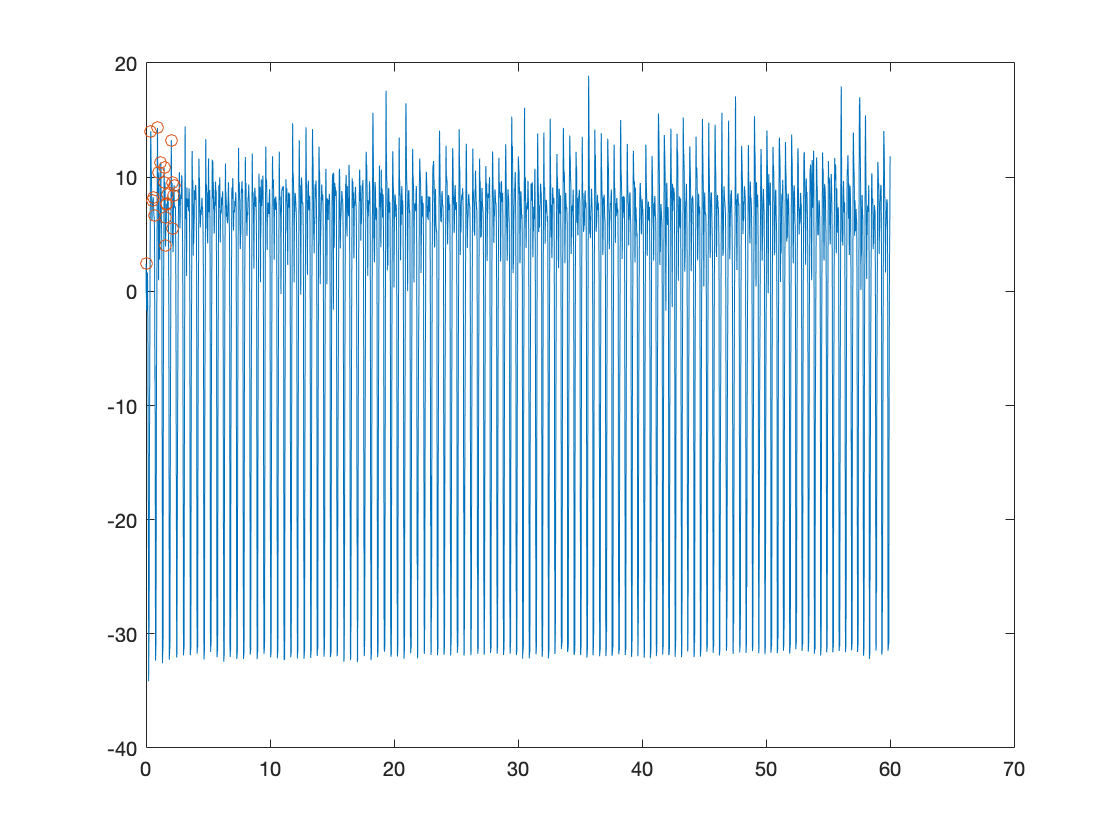

sjpkx1=sjpkx(:);

%acceleration of y
sja_y = sj_data(:,3);
[sjpkty,sjpky]=minamp20peaks(1.87,sjtime,sja_y);
plot(sjtime,sja_y)
hold on
plot(sjpkty,sjpky,'o')
hold off

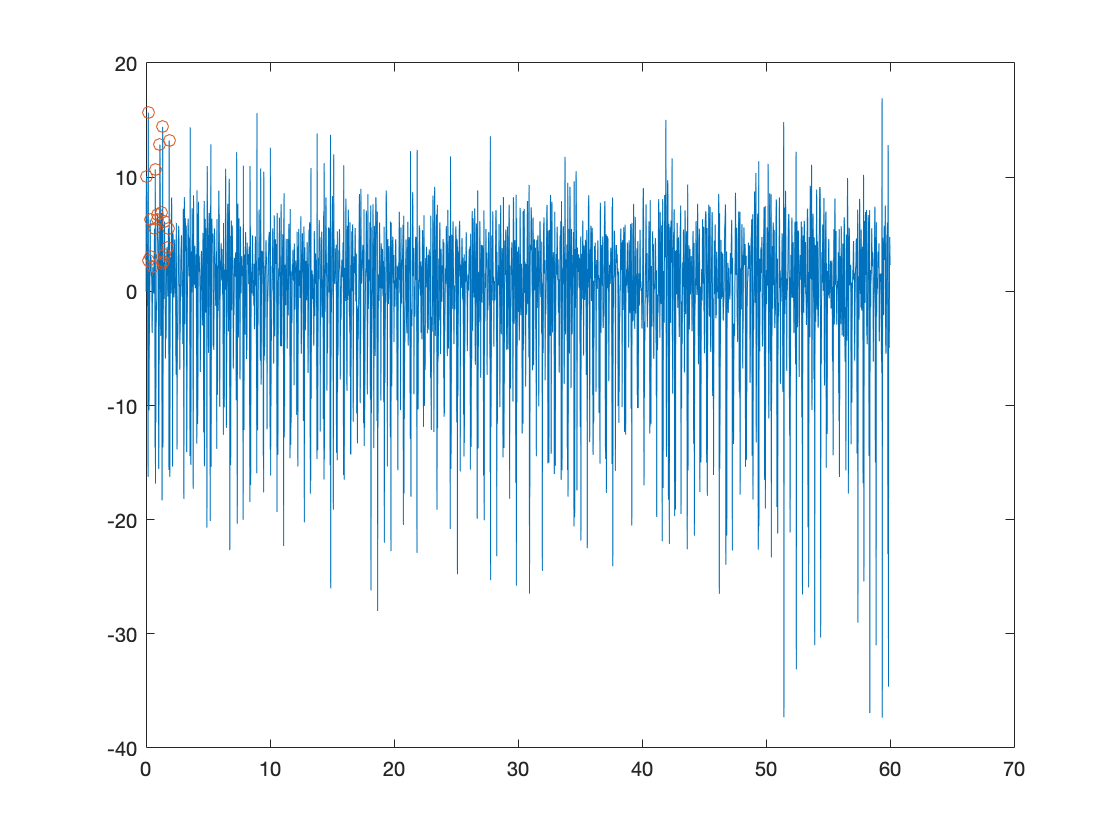

sjpky1=sjpky(:);

%acceleration of z
sja_z = sj_data(:,4);
[sjpktz,sjpkz]=minamp20peaks(1.87,sjtime,sja_z);
plot(sjtime,sja_z)
hold on
plot(sjpktz,sjpkz,'o')
hold off

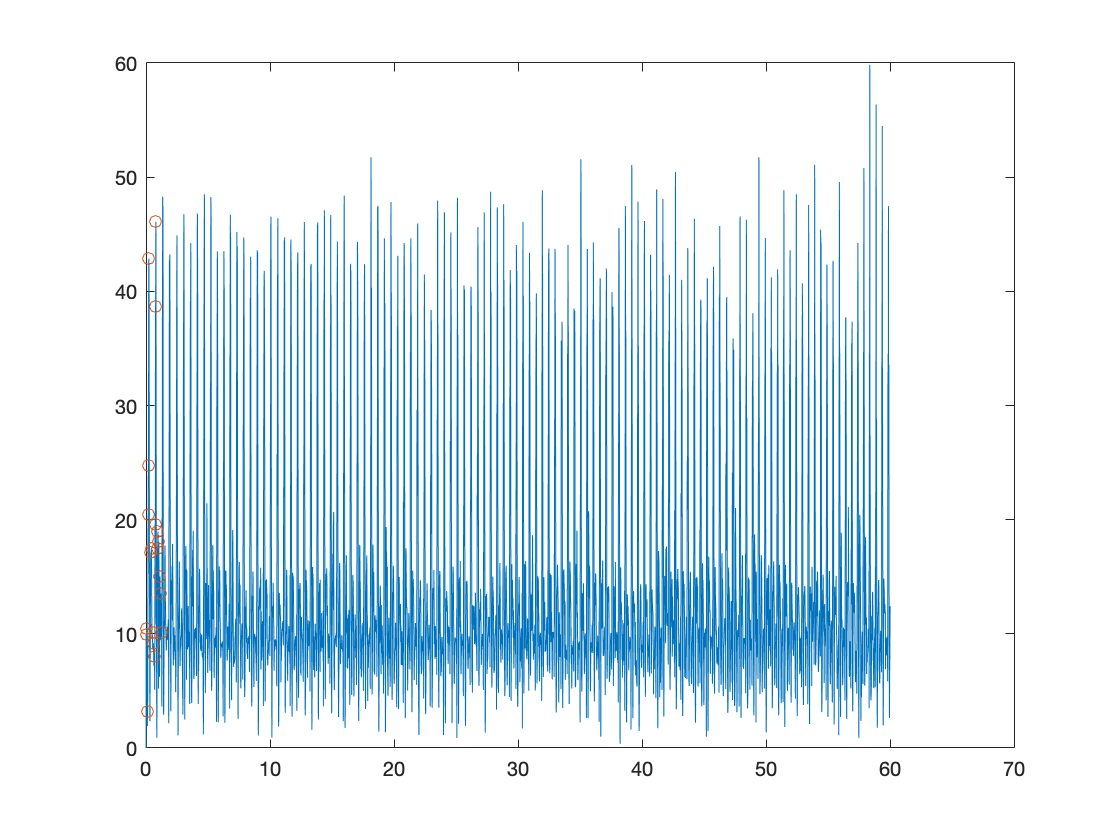

sjpkz1=sjpkz(:);

%absolute acceleration
sja_abs = sj_data(:,5);
[sjpkta,sjpka]=minamp20peaks(1.87,sjtime,sja_abs);
plot(sjtime,sja_abs)
hold on
plot(sjpkta,sjpka,'o')
hold off

sjpka1=sjpka(:);
sjpk=table(sjpkx1,sjpky1,sjpkz1,sjpka1,classj);
sjpk.Properties.VariableNames = ["A_xpeak","A_ypeak","A_zpeak","A_abspeak","Motion"]

sjpk = 20×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    7.3228      2.405     10.085      9.9331      "jumping"
    7.6989     14.037     15.656      10.429      "jumping"
    29.211     7.9669     2.7095      3.1599      "jumping"
    12.684     8.2507     6.2835      20.433      "jumping"
    32.169     6.6178     3.0325      24.766      "jumping"
    3.2712      14.31     2.1486       42.85      "jumping"
    33.338     10.427     5.5073      17.115      "jumping"
    10.049     11.306     10.686      17.484      "jumping"
    26.763     10.803      6.295      10.123      "jumping"
    26.442     9.5463     6.7698      9.1821      "jumping"
    6.2626     4.0474     12.848      8.0538      "jumping"
    3.4006     6.4663     6.883

%Combine peaks data
Featurespeak=[pwpk;prpk,;pjpk,;awpk;arpk;ajpk;swpk;srpk;sjpk]

Featurespeak = 180×5 table
    A_xpeak    A_ypeak    A_zpeak    A_abspeak     Motion  
    _______    _______    _______    _________    _________

    2.4943     3.1287     2.3911      2.3926      "walking"
    2.0844     2.2254     3.4871      1.8728      "walking"
    2.0786     5.1566     1.8741      3.4217      "walking"
    2.0767     1.8884     3.2401      3.6052      "walking"
     2.126     1.8724     2.4553      2.6861      "walking"
    2.1557     2.6988     4.1607      2.6986      "walking"
    2.0218     2.0506     2.1758      2.6641      "walking"
    2.5713     5.1342     2.2472      2.8081      "walking"
    2.3031     2.9543     2.4634      6.0767      "walking"
    2.2074     2.0821     2.3673      3.5403      "walking"
     2.754     3.9251     2.1506      3.4412      "walking"
    2.7467     2.3321 

[trainedClassifier, validationAccuracy]=trainClassifier(Featurespeak)

trainedClassifier = struct with fields:
                  predictFcn: @(x)naiveBayesPredictFcn(predictorExtractionFcn(x))
           RequiredVariables: {'A_abspeak'  'A_xpeak'  'A_ypeak'  'A_zpeak'}
    ClassificationNaiveBayes: [1×1 ClassificationNaiveBayes]
                       About: 'This struct is a trained model exported from Classification Learner R2020b.'
                HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy = 0.7222

function [x_p y_p] = minamp20peaks(v,x, y)
   
    x_p = [] ;
    y_p = [] ;
    a = 1 ; 
    
    for i = 1:length(x)
        if  i == 1 || i == length(x)
            a;
            continue
            
        elseif (y(i+1) < y(i)) && (y(i-1) < y(i)) && y(i)>v
            
                x_p(a) = x(i) ;
                y_p(a) = y(i) ;
                a = a + 1 ;
                
        elseif a>20
               a;
               break
        else 
            continue
                
        end
    
    end
end    

function [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% Returns a trained classifier and its accuracy. This code recreates the
% classification model trained in Classification Learner app. Use the
% generated code to automate training the same model with new data, or to
% learn how to programmatically train models.
%
%  Input:
%      trainingData: A table containing the same predictor and response
%       columns as those imported into the app.
%
%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy in percent. In
%       the app, the History list displays this overall accuracy score for
%       each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 02-May-2021 20:22:49


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'A_xpeak', 'A_ypeak', 'A_zpeak', 'A_abspeak'};
predictors = inputTable(:, predictorNames);
response = inputTable.Motion;
isCategoricalPredictor = [false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.

% Expand the Distribution Names per predictor
% Numerical predictors are assigned either Gaussian or Kernel distribution and categorical predictors are assigned mvmn distribution
% Gaussian is replaced with Normal when passing to the fitcnb function
distributionNames =  repmat({'Normal'}, 1, length(isCategoricalPredictor));
distributionNames(isCategoricalPredictor) = {'mvmn'};

if any(strcmp(distributionNames,'Kernel'))
    classificationNaiveBayes = fitcnb(...
        predictors, ...
        response, ...
        'Kernel', 'Normal', ...
        'Support', 'Unbounded', ...
        'DistributionNames', distributionNames, ...
        'ClassNames', {'jumping'; 'running'; 'walking'});
else
    classificationNaiveBayes = fitcnb(...
        predictors, ...
        response, ...
        'DistributionNames', distributionNames, ...
        'ClassNames', {'jumping'; 'running'; 'walking'});
end

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
naiveBayesPredictFcn = @(x) predict(classificationNaiveBayes, x);
trainedClassifier.predictFcn = @(x) naiveBayesPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'A_abspeak', 'A_xpeak', 'A_ypeak', 'A_zpeak'};
trainedClassifier.ClassificationNaiveBayes = classificationNaiveBayes;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2020b.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'A_xpeak', 'A_ypeak', 'A_zpeak', 'A_abspeak'};
predictors = inputTable(:, predictorNames);
response = inputTable.Motion;
isCategoricalPredictor = [false, false, false, false];

% Set up holdout validation
cvp = cvpartition(response, 'Holdout', 0.2);
trainingPredictors = predictors(cvp.training, :);
trainingResponse = response(cvp.training, :);
trainingIsCategoricalPredictor = isCategoricalPredictor;

% Train a classifier
% This code specifies all the classifier options and trains the classifier.

% Expand the Distribution Names per predictor
% Numerical predictors are assigned either Gaussian or Kernel distribution and categorical predictors are assigned mvmn distribution
% Gaussian is replaced with Normal when passing to the fitcnb function
distributionNames =  repmat({'Normal'}, 1, length(trainingIsCategoricalPredictor));
distributionNames(trainingIsCategoricalPredictor) = {'mvmn'};

if any(strcmp(distributionNames,'Kernel'))
    classificationNaiveBayes = fitcnb(...
        trainingPredictors, ...
        trainingResponse, ...
        'Kernel', 'Normal', ...
        'Support', 'Unbounded', ...
        'DistributionNames', distributionNames, ...
        'ClassNames', {'jumping'; 'running'; 'walking'});
else
    classificationNaiveBayes = fitcnb(...
        trainingPredictors, ...
        trainingResponse, ...
        'DistributionNames', distributionNames, ...
        'ClassNames', {'jumping'; 'running'; 'walking'});
end

% Create the result struct with predict function
naiveBayesPredictFcn = @(x) predict(classificationNaiveBayes, x);
validationPredictFcn = @(x) naiveBayesPredictFcn(x);

% Add additional fields to the result struct


% Compute validation predictions
validationPredictors = predictors(cvp.test, :);
validationResponse = response(cvp.test, :);
[validationPredictions, validationScores] = validationPredictFcn(validationPredictors);

% Compute validation accuracy
correctPredictions = strcmp( strtrim(validationPredictions), strtrim(validationResponse));
isMissing = cellfun(@(x) all(isspace(x)), validationResponse, 'UniformOutput', true);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);


% Compute validation accuracy
correctPredictions = strcmp( strtrim(validationPredictions), strtrim(validationResponse));
isMissing = cellfun(@(x) all(isspace(x)), validationResponse, 'UniformOutput', true);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);
end